## Initialize

addpath('./utilities/plotSpread');
addpath('./utilities/distributionPlot')
addpath('./utilities/subaxis/');

%this tells matlab where to look for the data files included as part of
%this supplemental files. please change your working directory to the
%folder containing this script and associated data files
r_path='./data/';

## Post-inoculation smFISH

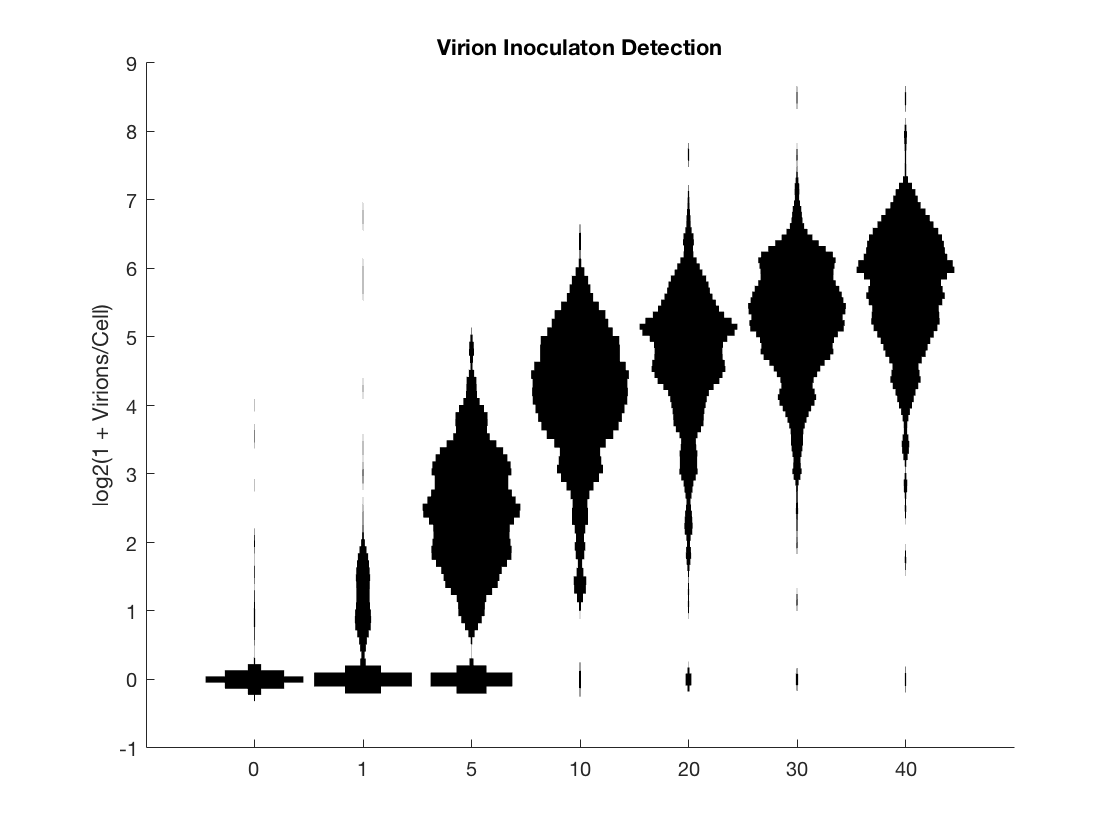

%Figures 2C, S1A, and S1B

stack_name={'D5','C1','C2','C3','C4','C5','C6'};
labels={'0','1','5','10','20', '30','40'};
dat_555={};
d555={};
figCN=figure; hold all; 
for s=1:length(stack_name)
    x=readtable(fullfile(r_path,'inoc_smfish',[stack_name{s},'_FishCountsoutput.csv']));
    dat_555_log{s}=log2(1+x.Fish_Ch555_long./x.CellArea*mean(x.CellArea));
    dat_555{s}=x.Fish_Ch555_long./x.CellArea*mean(x.CellArea);
    figure(figCN), cdfplot(dat_555{s})
end

%Figure 2C
figure, distributionPlot(dat_555_log,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2), title('Virion Inoculaton Detection'), ylabel('log2(1 + Virions/Cell)')
xticklabels(labels)

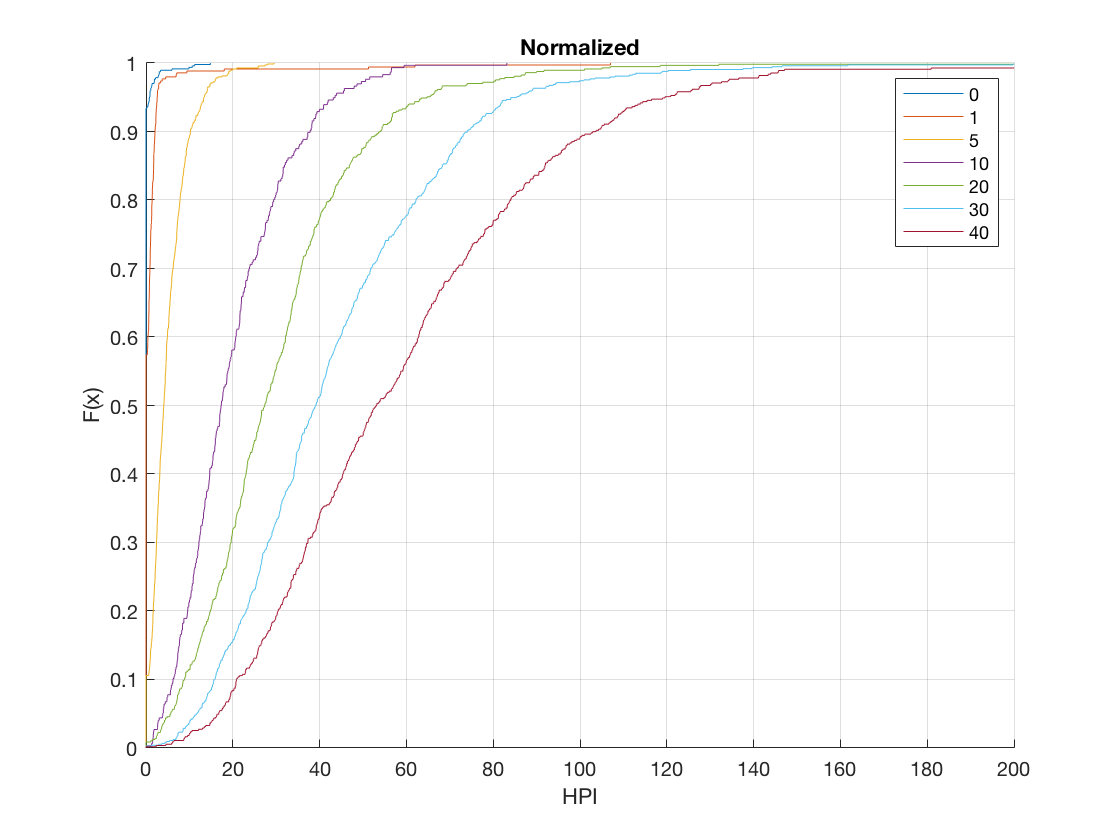

%Figure S1A
figure(figCN), legend(labels), title('Normalized');  xlim([0 200])

%Figure S1B
stack_name={'D5','B6','B4','B2','A6'};
labels={'Blank','1','2','3','4'}; %hpi
xlabel('HPI')

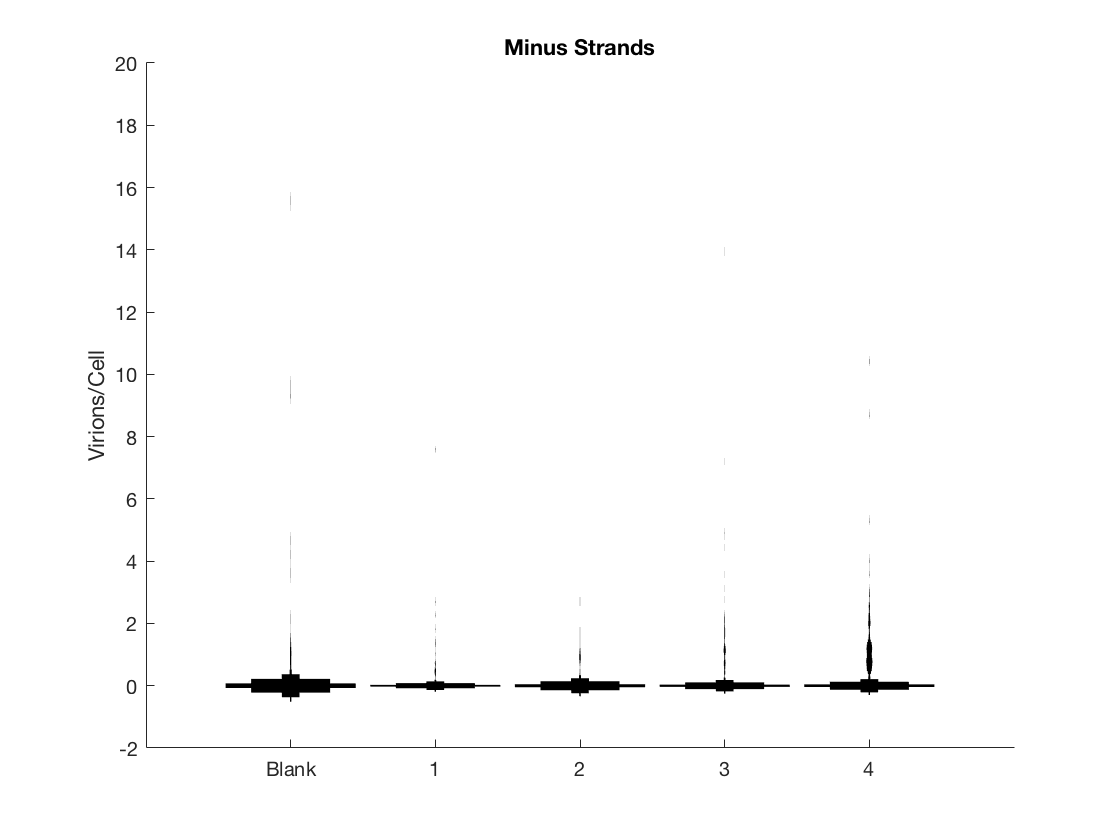

dat_594={};

for s=1:length(stack_name)
    x=readtable(fullfile(r_path,'inoc_smfish',[stack_name{s},'_FishCountsoutput_6h_594.csv']));
    dat_594{s}=x.Fish_Ch594./x.CellArea*mean(x.CellArea);
end
figure, distributionPlot(dat_594,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2), title('Minus Strands'), ylabel('Virions/Cell')
xticklabels(labels), ylim([-2 20])

## Early-timepoint smFISH 

%Figures 2E, and S2A

stack_name={'A3','A6','B3','B6','C3','D1'}; stack_name=flip(stack_name);
labels={'2.5','2', '1.5', '1', '0.5', 'Blank'}; labels=flip(labels);

dat_555={};
dat_647={};
dat_turq={};

numCells=0;
for s=1:length(stack_name)
    x=readtable(fullfile(r_path,'early_smfish',[stack_name{s},'_FishCountsoutput.csv']));
    dat_turq{s}=log2(1+x.Fish_ChTurq_on_1);
    dat_555{s}=log2(1+x.Fish_Ch555_long);
    dat_647{s}=log2(1+x.Fish_ChCy5);
    numCells=numCells+size(x.Fish_ChCy5,1);
end
numCells

numCells = 3553

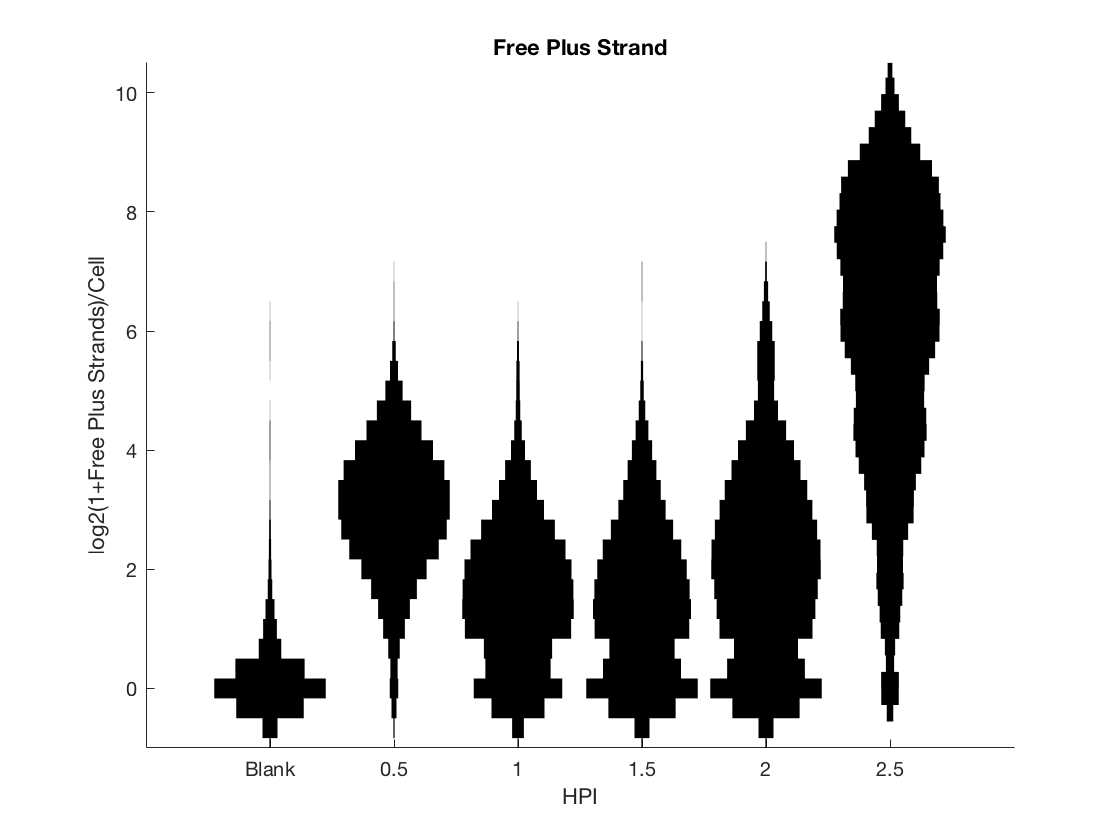

%Figure 2E
figure, distributionPlot(dat_555,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2), title('Free Plus Strand'),xticklabels(labels), ylim([-1 10.5]),ylabel('log2(1+Free Plus Strands)/Cell'),xlabel('HPI')

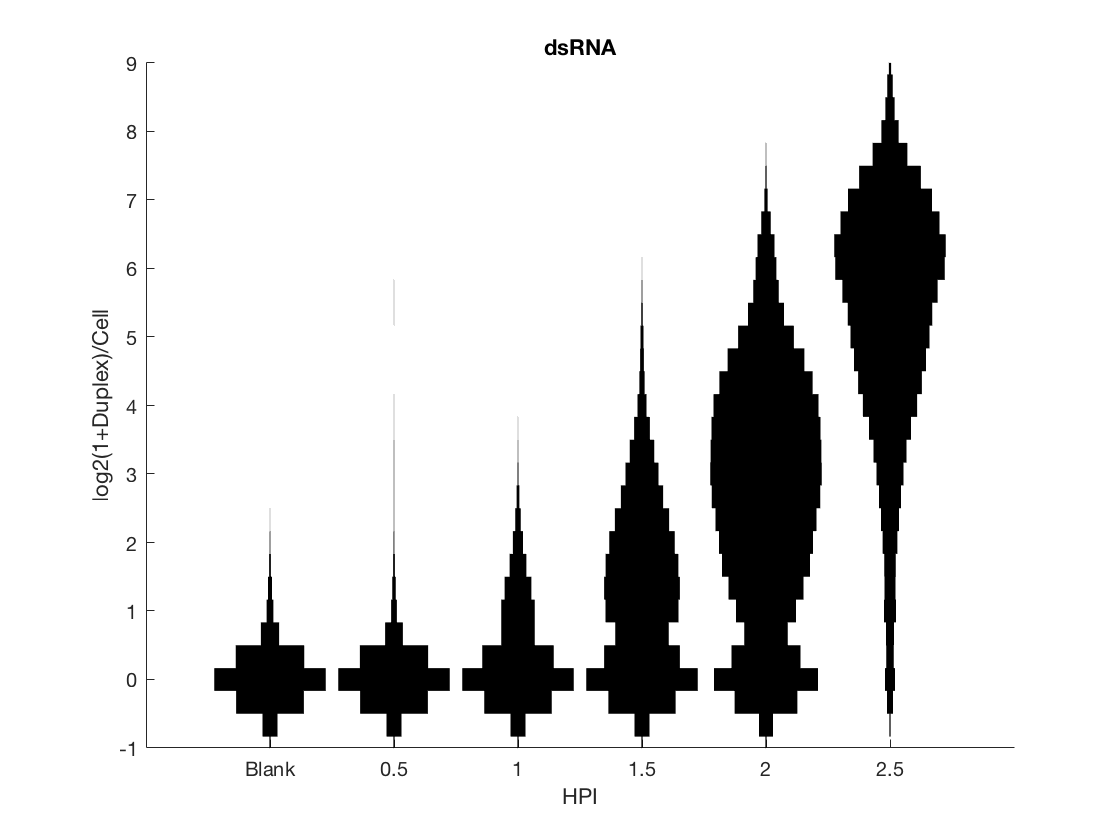

figure, distributionPlot(dat_647,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2), title('dsRNA'),xticklabels(labels), ylim([-1 9]),ylabel('log2(1+Duplex)/Cell'),xlabel('HPI')

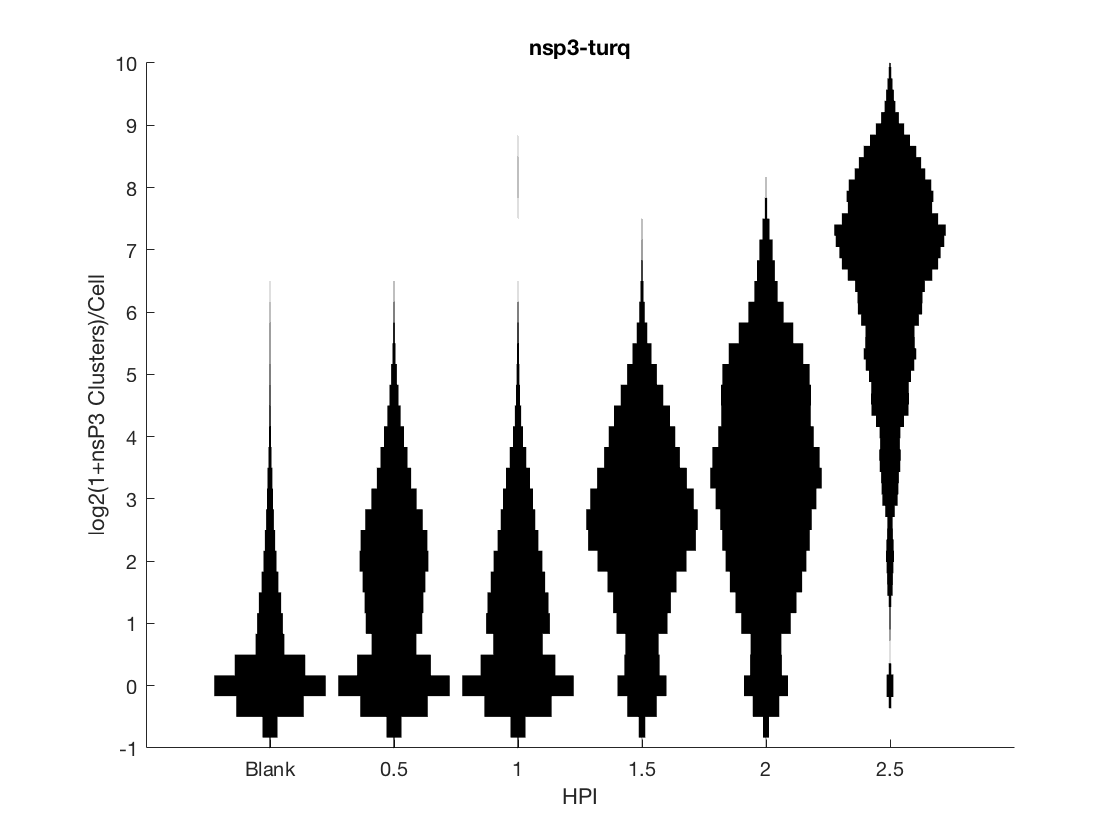

%Figure S2A
figure, distributionPlot(dat_turq,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2), title('nsp3-turq'),xticklabels(labels), ylim([-1 10]),ylabel('log2(1+nsP3 Clusters)/Cell'),xlabel('HPI')

## 8h timecourse total fluor FISH and nsP3-Turq quantification and trajectories

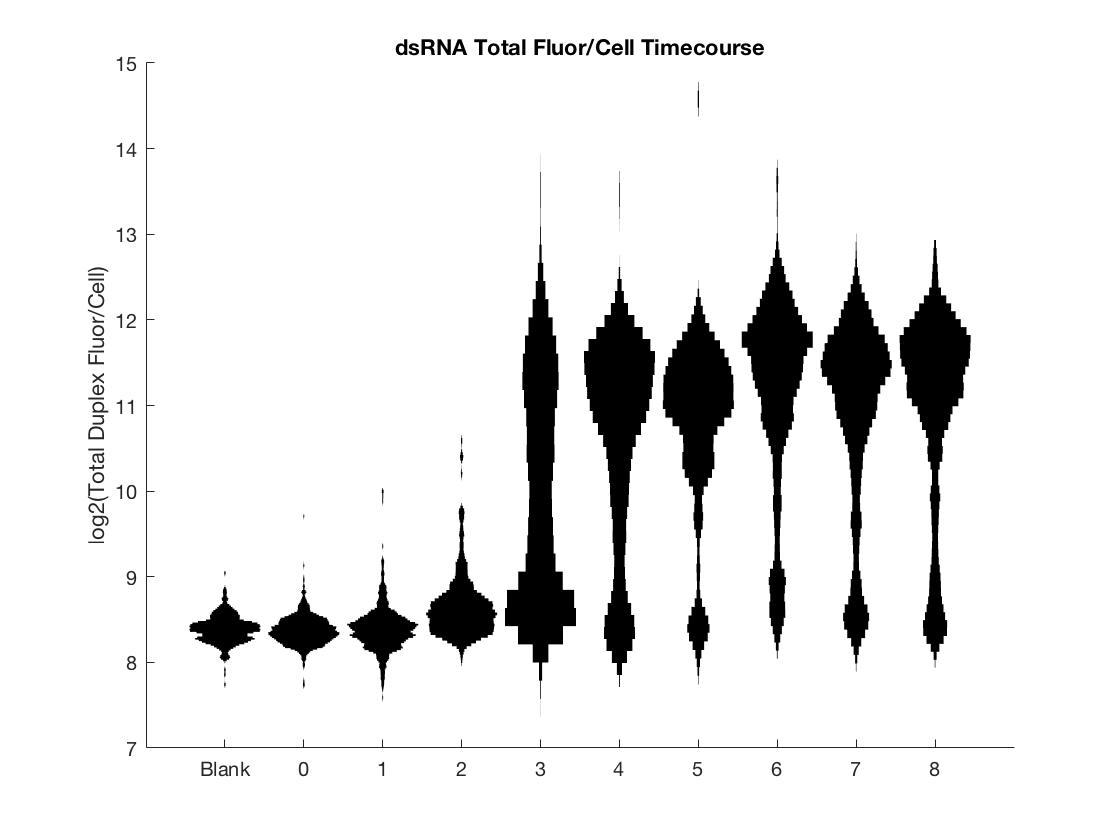

stack_name=flip({'A3','A4','A5','A6','B1','B2','B3','B4','B5','B6'});
labels=flip({'8','7','6','5','4','3','2','1','0','Blank'});
dat={};
for g=1:length(stack_name)
    load(fullfile(r_path,'8hr_timecourse',[stack_name{g},'-stats.mat']),'stats');
    good=stats(:,3)>5000;
    dat{g}=log2(stats(good,7)./stats(good,3));
end

%Figure 2F
figure
distributionPlot(dat,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2)
set(gca,'xticklabel',labels), title('dsRNA Total Fluor/Cell Timecourse')
ylabel('log2(Total Duplex Fluor/Cell)')

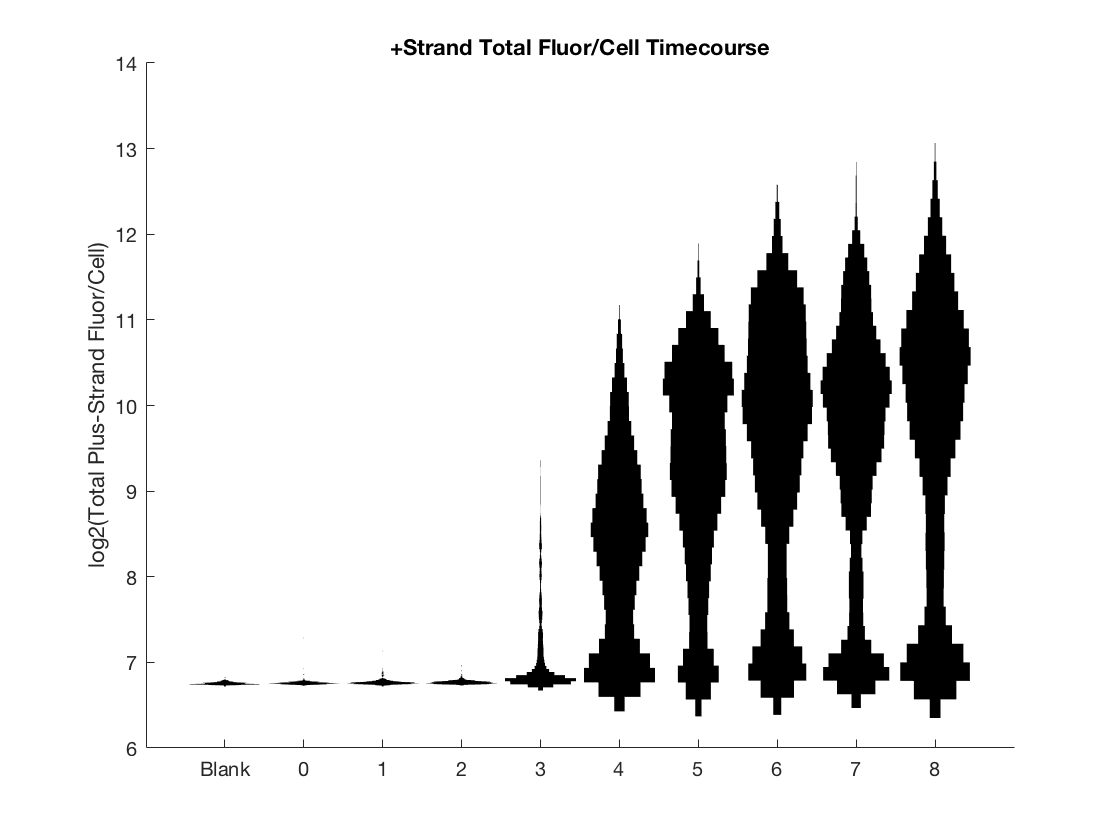


dat={};good=[];
for g=1:length(stack_name)
    load(fullfile(r_path,'8hr_timecourse',[stack_name{g},'-stats.mat']),'stats');
    good=stats(:,3)>5000;
    dat{g}=log2(stats(good,5)./stats(good,3));
end
figure
distributionPlot(dat,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2)
title('+Strand Total Fluor/Cell Timecourse');
set(gca,'xticklabel',labels)
ylabel('log2(Total Plus-Strand Fluor/Cell)')

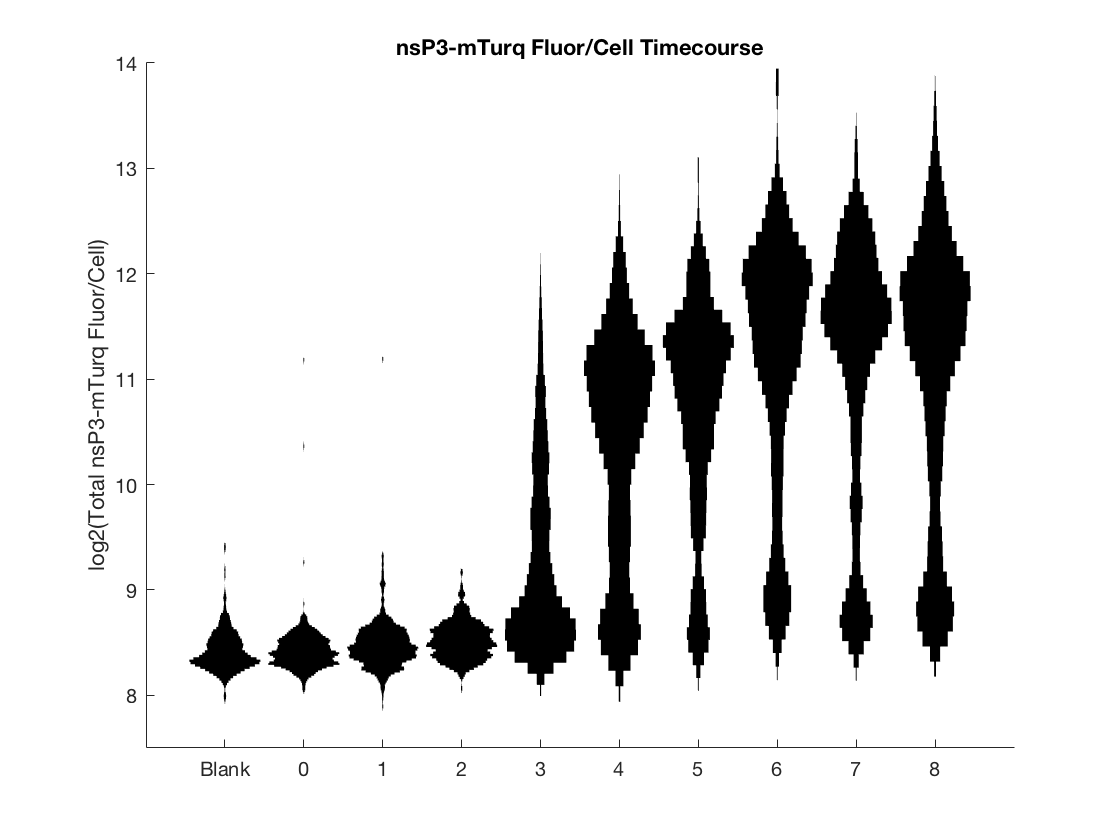




dat={};
for g=1:length(stack_name)
    load(fullfile(r_path,'8hr_timecourse',[stack_name{g},'-stats.mat']),'stats');
    good=stats(:,3)>5000;
    dat{g}=log2(stats(good,4)./stats(good,3));

end
%Figure 3C
figure
distributionPlot(dat,'globalNorm',0,'histOpt',1.1,'showMM',0,'divFactor',2), title('nsP3-mTurq Fluor/Cell Timecourse');
set(gca,'xticklabel',labels)
ylabel('log2(Total nsP3-mTurq Fluor/Cell)')
ylim([7.5 14])

dat={};
for g=1:length(stack_name)
    load(fullfile(r_path,'8hr_timecourse',[stack_name{g},'-stats.mat']),'stats');
    good=stats(:,3)>5000;
    numCells=numCells+length(find(good));
    dat{g}=(stats(good,4)-200*stats(good,3)); %200 for bg subtraction
end

stack_name={'A3','A4','A5','A6','B1','B2','B3','B4','B5','B6'};

C=[165,0,38;
215,48,39;
244,109,67;
253,174,97;
255,255,191;
224,243,248;
171,217,233;
69,117,180;
49,54,149]/255;
colormap(C)


f1=figure; colormap(C); hold all; f2=figure; colormap(C); hold all; f3=figure; colormap(C); hold all;
all57=[];
all45=[];
all47=[];
for g=1:length(stack_name)
    load(fullfile(r_path,'8hr_timecourse',[stack_name{g},'-stats.mat']),'stats');
    good=stats(:,3)>3000;
    figure(f1); scatter(log2(stats(good,5)./stats(good,3)),log2(stats(good,7)./stats(good,3)),[],g*ones(size(find(good),1),1)); ylim([7 13])
    all57=[all57; log2(stats(good,5)./stats(good,3)), log2(stats(good,7)./stats(good,3))];
    figure(f2); scatter(log2(stats(good,4)./stats(good,3)),log2(stats(good,5)./stats(good,3)),[],g*ones(size(find(good),1),1));
    all45=[all45; log2(stats(good,4)./stats(good,3)), log2(stats(good,5)./stats(good,3))];
    figure(f3); scatter(log2(stats(good,4)./stats(good,3)),log2(stats(good,7)./stats(good,3)),[],g*ones(size(find(good),1),1));
    all47=[all47; log2(stats(good,4)./stats(good,3)), log2(stats(good,7)./stats(good,3))];
end
%Figure 2H
figure(f1); xlabel('log_2(Mean Fluor Plus-Strand)'),ylabel('log_2(Mean Fluor Duplex)')
corrcoef(all57(:,1),all57(:,2))

ans =     1.0000    0.8366
    0.8366    1.0000


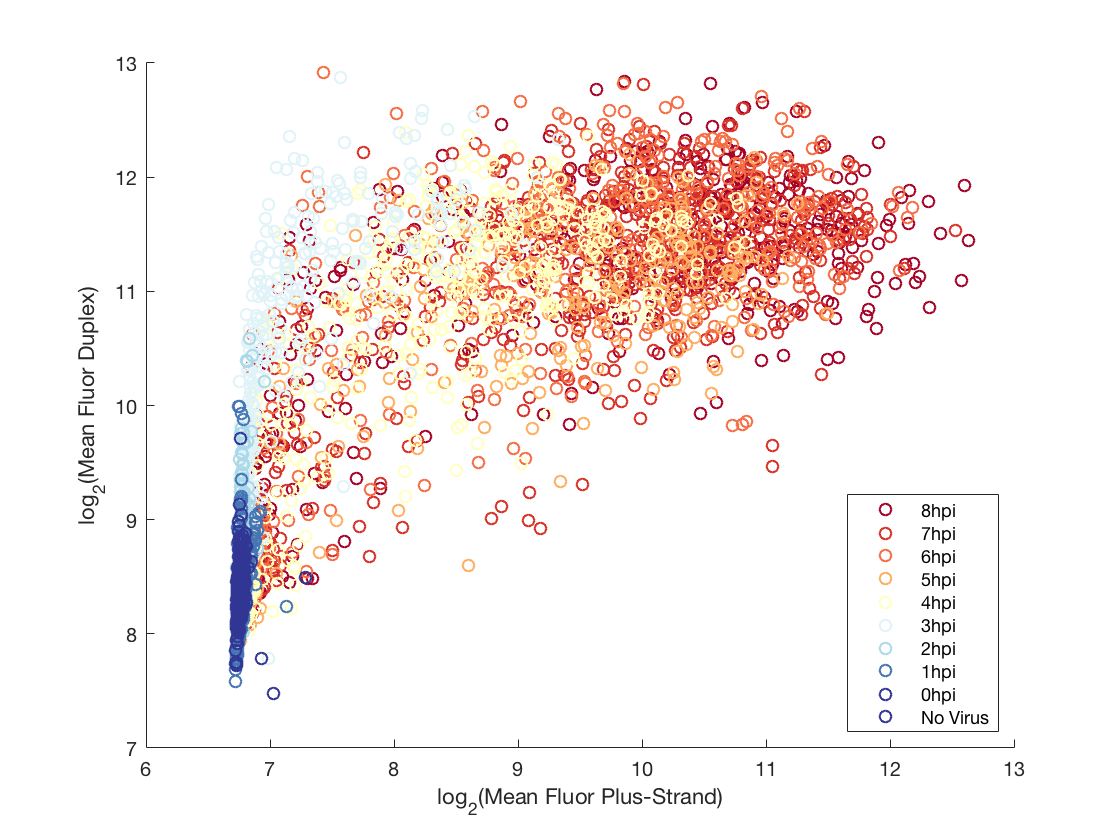

legend({'8hpi','7hpi','6hpi','5hpi','4hpi','3hpi','2hpi','1hpi','0hpi','No Virus'},'Location','SE')

%Figure 3E
figure(f2); ylabel('log_2(Mean Fluor +Strand)'),xlabel('log_2(Mean Fluor Turq)')
corrcoef(all45(:,1),all45(:,2))

ans =     1.0000    0.9001
    0.9001    1.0000


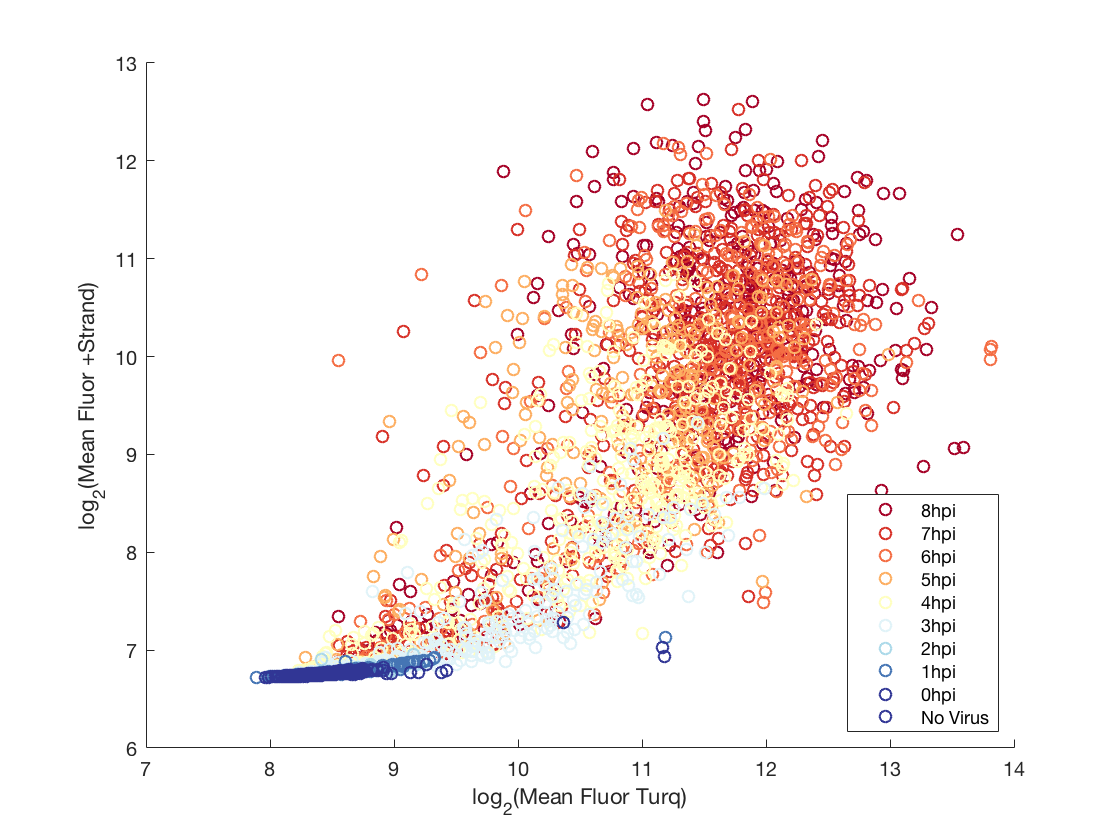

legend({'8hpi','7hpi','6hpi','5hpi','4hpi','3hpi','2hpi','1hpi','0hpi','No Virus'},'Location','SE')

%Figure 3D
figure(f3); xlabel('log_2(Mean Fluor mTurquoise)'),ylabel('log_2(Mean Fluor Duplex)')
corrcoef(all47(:,1),all47(:,2))

ans =     1.0000    0.9157
    0.9157    1.0000


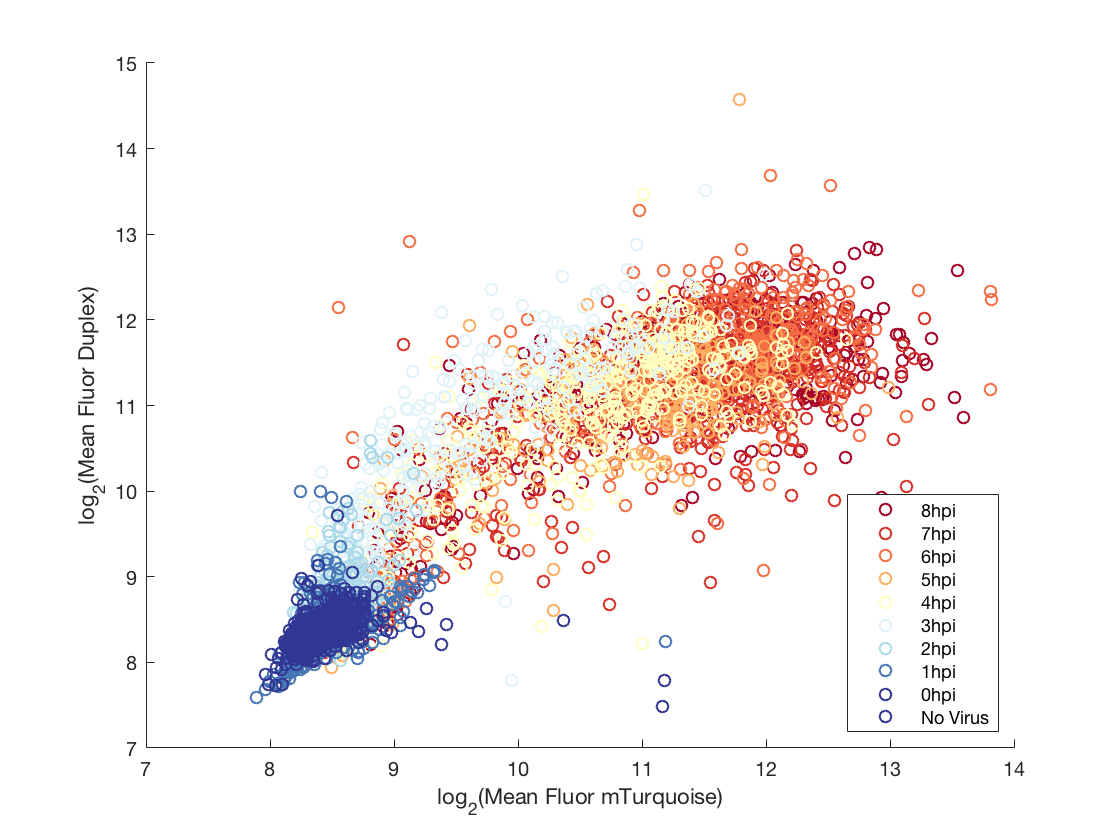

legend({'8hpi','7hpi','6hpi','5hpi','4hpi','3hpi','2hpi','1hpi','0hpi','No Virus'},'Location','SE')

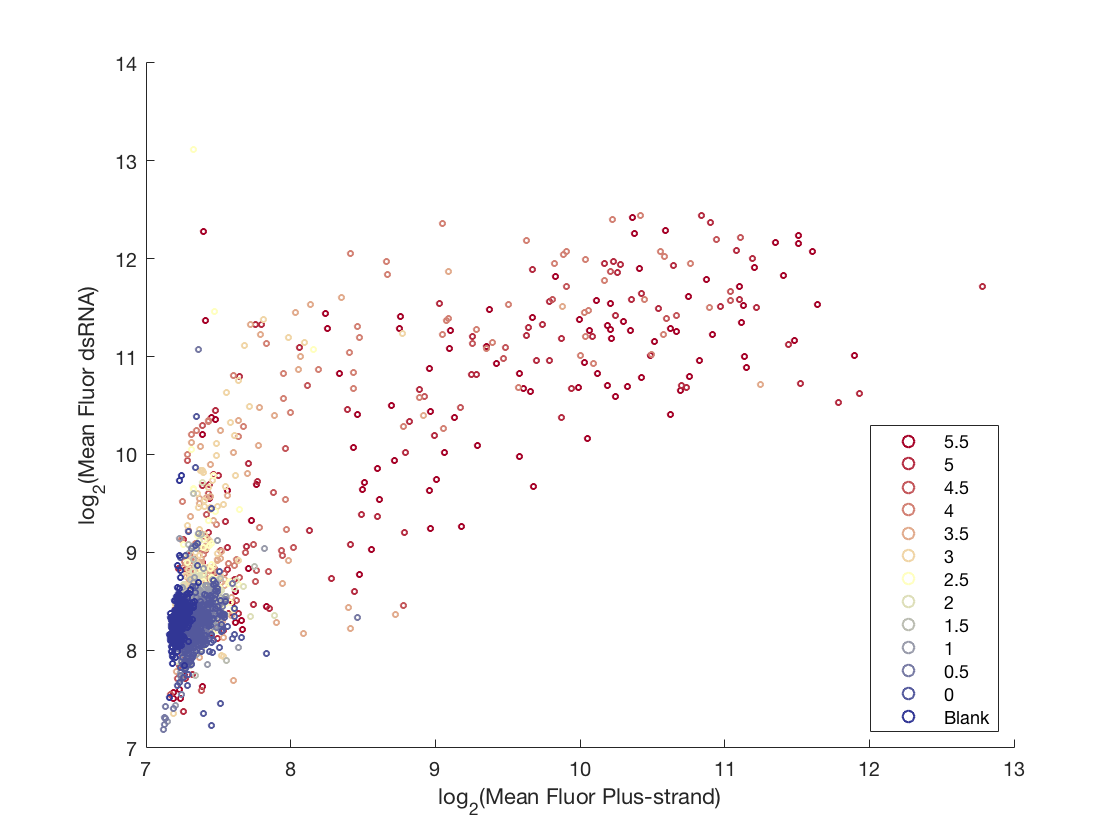


C=[165,0,38;
215,48,39;
244,109,67;
253,174,97;
255,255,191;
224,243,248;
171,217,233;
69,117,180;
49,54,149]/255;
C=flip(C);

cmap(1,:)=C(9,:); cmap(2,:)=C(5,:); cmap(3,:)=C(1,:);
[X,Y]=meshgrid(1:3,1:13);
C = interp2(X([1,7,13],:),Y([1,7,13],:),cmap,X,Y);

groups={'Plate2_B6','Plate1_A1','Plate1_A2','Plate1_A3','Plate1_A4','Plate1_A5','Plate1_A6','Plate1_B1','Plate1_B2','Plate1_B3','Plate1_B4','Plate1_B5','Plate1_B6'}; %blank well for Cy5 is Plate2_b6, 555 is Plate2_A6
labels={'Blank','0','0.5','1','1.5','2','2.5','3','3.5','4','4.5','5','5.5'};

%Figure 2C
groups=flip(groups);
labels=flip(labels);
f2=figure; hold all;
for g=1:length(groups)
    load(fullfile(r_path,'moi1_smfish',[groups{g},'-stats.mat']),'stats');
    good=stats(:,3)>3000;
    figure(f2); scatter(log2(stats(good,5)./stats(good,3)),log2(stats(good,6)./stats(good,3)),8*ones(length(find(good)),1),repmat(C(g,:),size(find(good),1),1));
end

xlabel('log_2(Mean Fluor Plus-strand)')
ylabel('log_2(Mean Fluor dsRNA)')
legend(labels,'Location','SE')

## Fitting single-color traces

ub =            1      700000



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 

mean: 0.034075 std: 0.017989


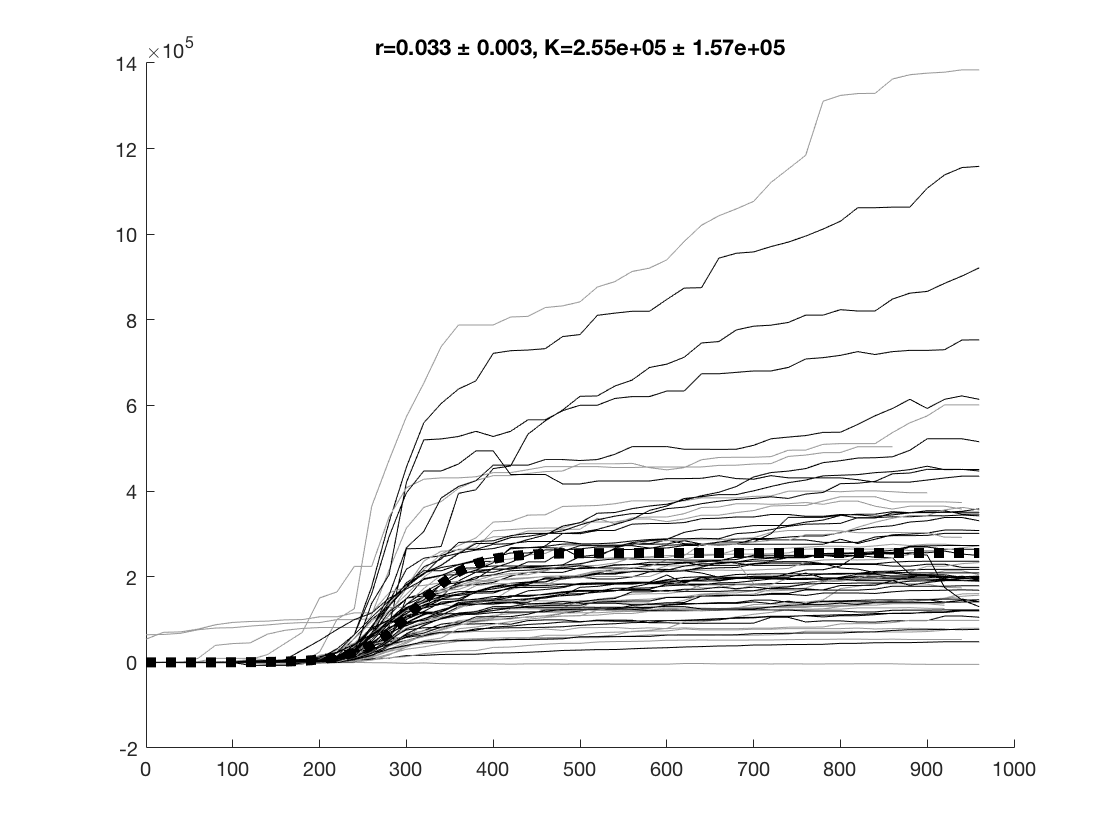

ub =            1      700000



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 

mean: 0.031014 std: 0.0062301


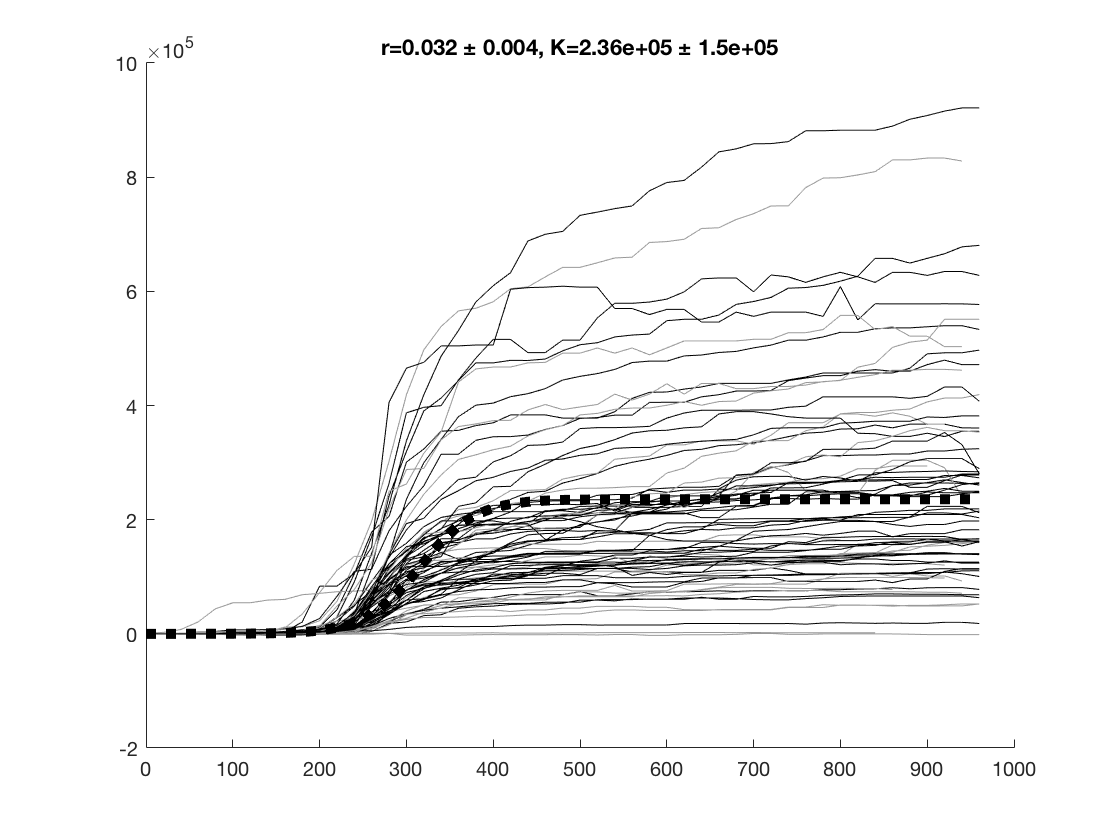

ub =            1      700000



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the 

mean: 0.038414 std: 0.030894


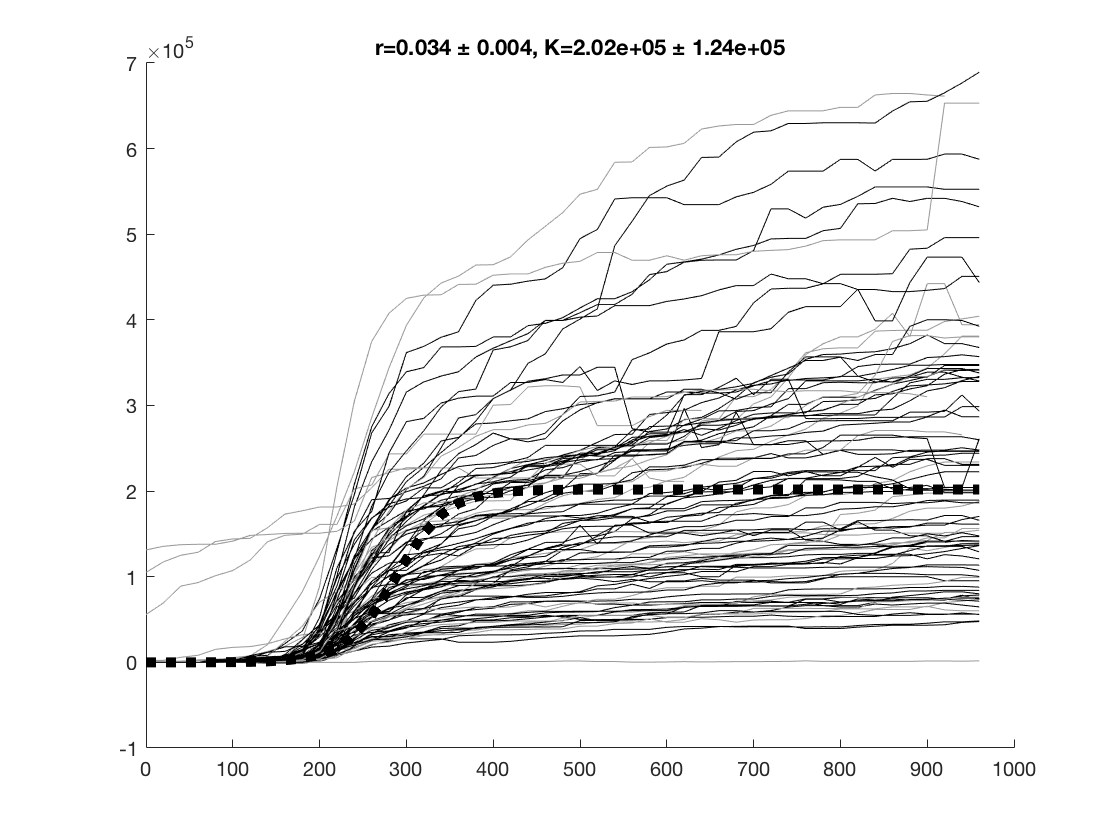

sets={'B1','B2','C1'}; %MOI 5, 10, 20 respectively
M0=[1, 5,10,20];

for sampleNum=1:length(sets)
    dat=load(fullfile(r_path,'single_virus_traces',[sets{sampleNum},'_Tracedata_Cit.mat']),'Tracedata_Cit');
    sample=cell2mat(dat.Tracedata_Cit');
    sample=medfilt1(sample,5,[],2);
    sample=sample-repmat(sample(:,1),1,size(sample,2));
    sample=[repmat(sample(:,1),[1 3]), sample]; %compensate for time not imaged
    n=sample./repmat(mean(sample(:,end-10:end),2),1,size(sample,2));
    medianAtEnd=median(sample(:,end));
    n2e5=2e5*sample./medianAtEnd;
    endAt=2e5;
    
    slope_cit= movmean(diff(n,1,2),3,2);
    slope_cit_max = max(slope_cit,[],2);
    
    Tmslopemax=[];
    for i=1:size(slope_cit,1)
        Tmslopemax(i)=find(slope_cit(i,:)==slope_cit_max(i),1,'first');
    end
    alignTo=round(mean(Tmslopemax(:)));
    
    aligned2e5RescaledNaNpadded={};
    shiftVector=[];
    for i=1:size(n2e5,1)
        shift=Tmslopemax(i)-alignTo;
        shiftVector(i)=shift;
        if shift>0 %shift left
            thisTrace=[n2e5(i,shift:end) NaN(1,shift-1)];
        elseif shift<0 %shift right
            thisTrace=[n2e5(i,1)*ones(1,abs(shift)) n2e5(i,1:end-abs(shift))];
        else
            thisTrace=n2e5(i,:);
        end
        aligned2e5RescaledNaNpadded{i}=thisTrace;
    end
    
    aligned2e5RescaledUnpadded={};
    shiftVector=[];
    for i=1:size(n2e5,1)
        shift=Tmslopemax(i)-alignTo;
        shiftVector(i)=shift;
        if shift>0 %shift left
            thisTrace=[n2e5(i,shift:end)];
        elseif shift<0 %shift right
            thisTrace=[n2e5(i,1)*ones(1,abs(shift)) n2e5(i,1:end-abs(shift))];
        else
            thisTrace=n2e5(i,:);
        end
        aligned2e5RescaledUnpadded{i}=thisTrace;
    end
    
    
    %%%%fit to rescaled and shifted unpadded also varying K
    K=endAt;
    P_0=10;
    r_0=0.03;
    params=[r_0,endAt];
    logistic = @(params,t)params(2)./(1+((params(2)-P_0))/P_0*exp(-params(1)*t));
    figure
    lb=[0 3e4];
    ub=[1 7e5]
    allRs=[];
    resnorms=[];
    for i=1:length(aligned2e5RescaledUnpadded)
        thisF=aligned2e5RescaledUnpadded{i};
        timepoints=0:20:20*length(thisF)-1;
        [thisR, resnorms(i)]=lsqcurvefit(logistic,params,timepoints,thisF,lb,ub);
        allRs(i,:)=thisR;
    end
    a=allRs;
    disp(['mean: ',num2str(mean(a(:,1))),' std: ',num2str(std(a(:,1)))])
    
    longestTime=0;
    for i=1:length(aligned2e5RescaledUnpadded)
        thisF=aligned2e5RescaledUnpadded{i};
        timepoints=0:20:20*length(thisF)-1;
        longestTime=max(longestTime,timepoints(end));
    end
    
    figure; hold all;
    maxLength=0;
    itsFlat=[];
    foldChange=[];
    for i=1:length(aligned2e5RescaledNaNpadded)
        timepoints=0:20:20*length(aligned2e5RescaledNaNpadded{i})-1;
        foldChange(i)=aligned2e5RescaledNaNpadded{i}(end)/aligned2e5RescaledNaNpadded{i}(end-12);
        itsFlat(i)=foldChange(i)<=1.2 & aligned2e5RescaledNaNpadded{i}(end)/aligned2e5RescaledNaNpadded{i}(1)>10;
        if itsFlat(i)
            plot(timepoints,aligned2e5RescaledNaNpadded{i},'Color','k');
        elseif ~itsFlat(i)
            plot(timepoints,aligned2e5RescaledNaNpadded{i},'Color',[0.6 0.6 0.6]);
        end
        maxLength=max(maxLength,length(aligned2e5RescaledNaNpadded{i}));
    end
    timepoints=0:20:20*(maxLength)-1;
    plot(timepoints,logistic([mean(allRs(find(itsFlat),1)),mean(allRs(find(itsFlat),2))],timepoints),':k','LineWidth',5)
    title(sprintf('r=%0.3f ± %0.3f, K=%0.3g ± %0.3g',mean(allRs(find(itsFlat),1)),std(allRs(find(itsFlat),1)),mean(allRs(find(itsFlat),2)),std(allRs(find(itsFlat),2))));
end

## Compute distributions of fold change in movie slopes

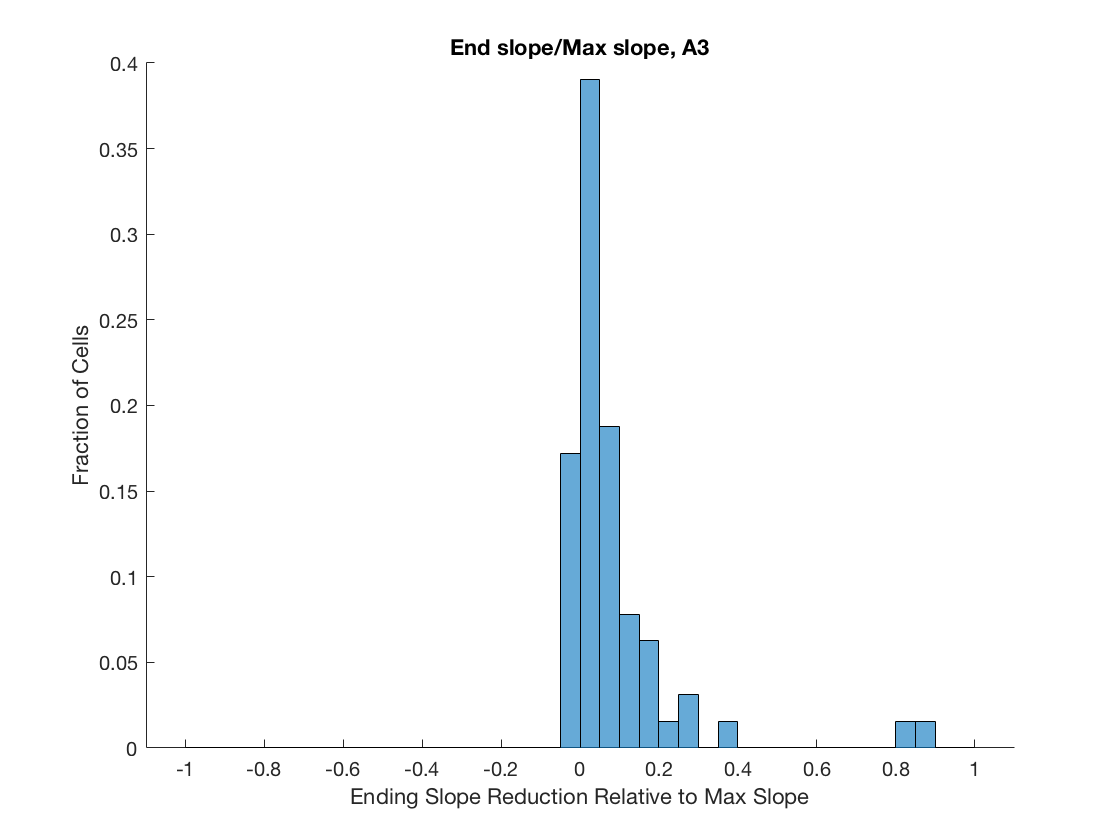

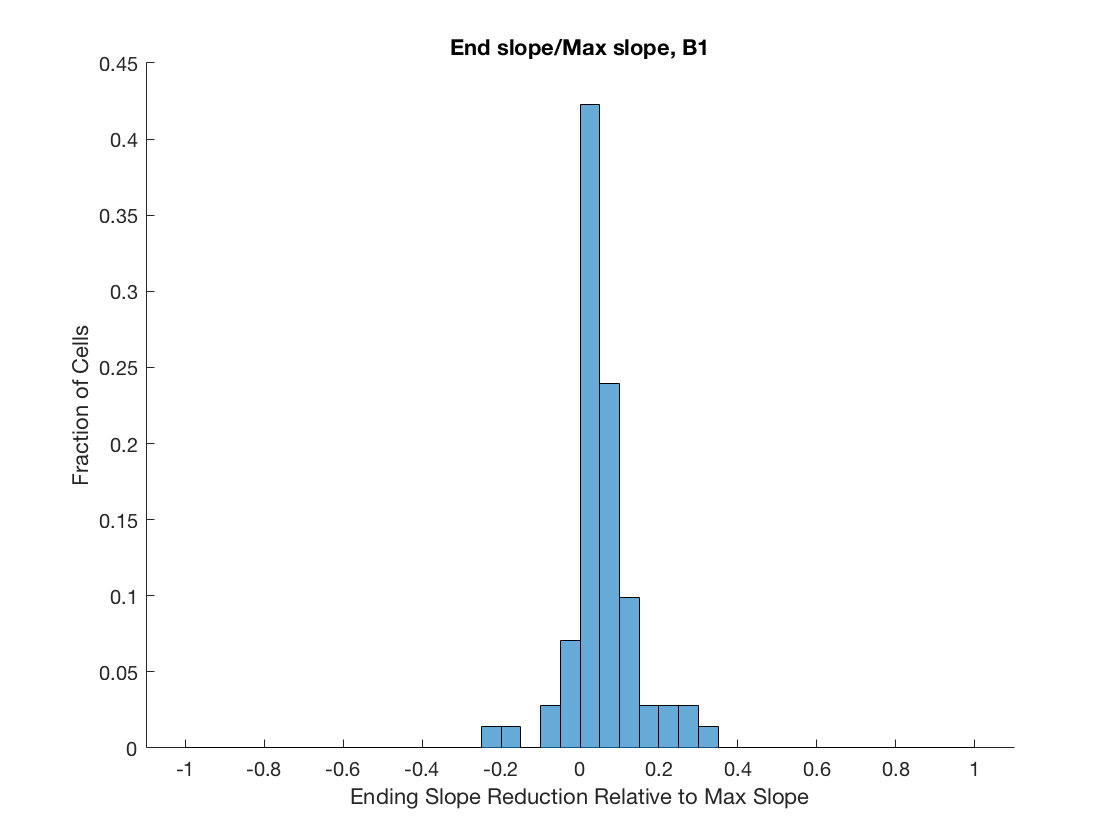

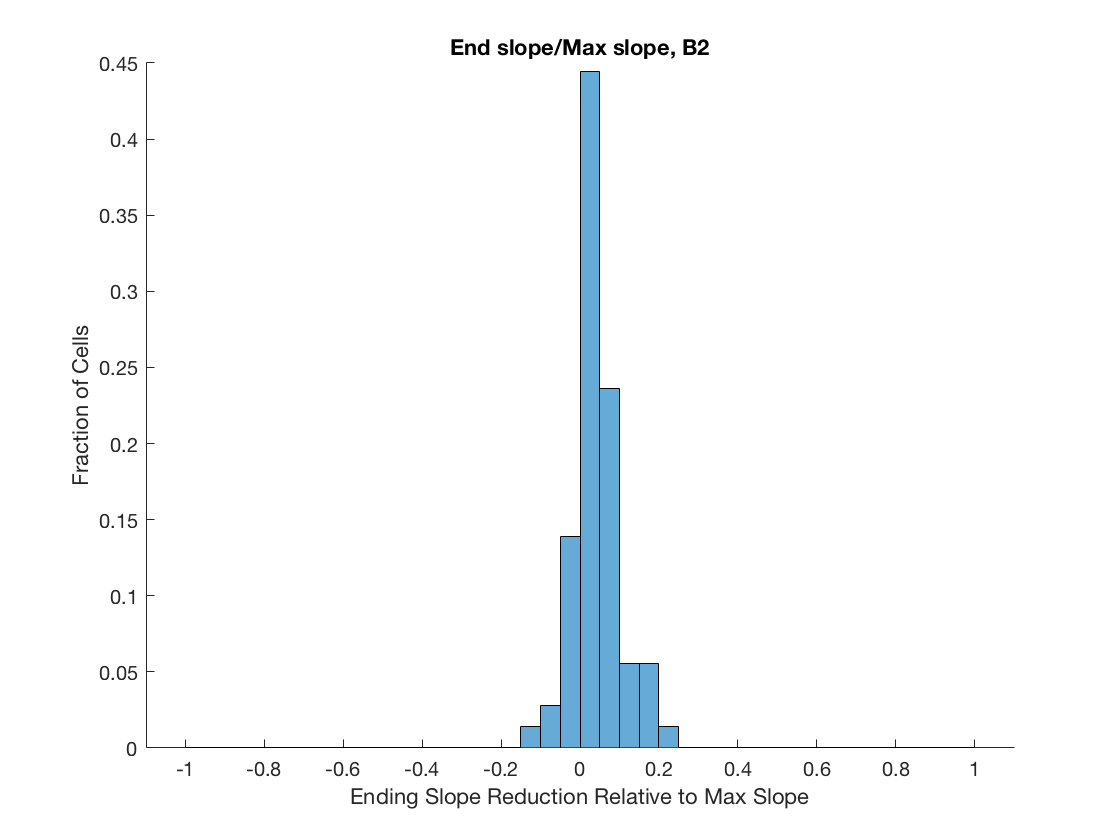

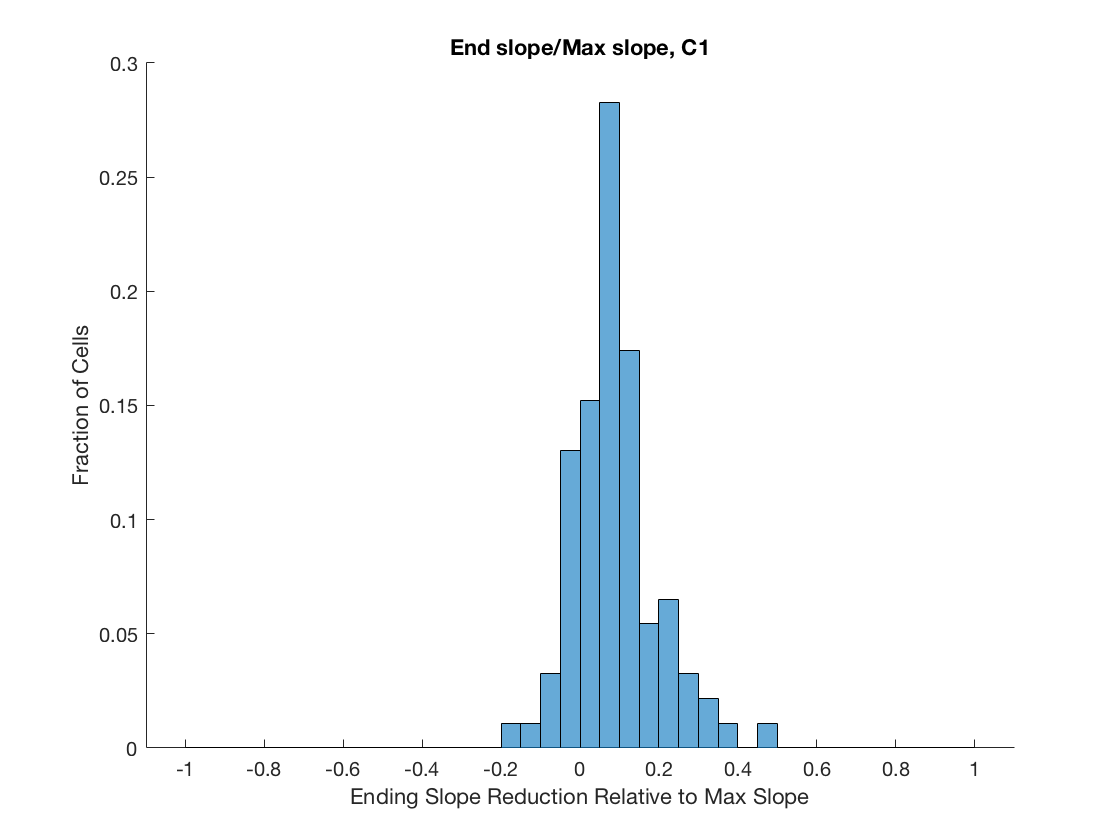

%Figs 3H, S2C

meanReduction=[];
stdOfReduction=[];

sets={'A3','B1','B2','C1'}; %MOI 1, 5, 10, 20 respectively
M0=[1, 5,10,20];
for sampleNum=1:length(sets)
    dat=load(fullfile(r_path,'single_virus_traces',[sets{sampleNum},'_Tracedata_Cit.mat']),'Tracedata_Cit');
    thisSet=cell2mat(dat.Tracedata_Cit');

    
    thisSet=medfilt1(thisSet,5,[],2);
    
    thisSetslope_cit= diff(thisSet,1,2);
    thisSetslope_cit_max = max(thisSetslope_cit,[],2);
    findRealMax=[];
    TthisSetslopemax=[];
    for i=1:size(thisSetslope_cit,1)
        thisTrace=thisSet(i,:);
        firstDiff=diff(thisTrace,1);
        secondDiff=diff(thisTrace,2);
        
        thisMap=[[1:length(thisTrace)-2]'  firstDiff(1:end-1)' secondDiff'];
        sortedMap=sortrows(thisMap,2,'descend');
        success=0;
        for j=1:3
            if firstDiff(sortedMap(j,1)+1) > 0
                TthisSetslopemax(i)=sortedMap(j,1);
                success=1;
                break;
            end
        end
        if ~success
            TthisSetslopemax(i)=-1;
        end
    end
    
    fragmentLength=12;
    ratios=[];
    
    for i=1:size(thisSet,1)
        timepoints=0:20:20*(size(thisSet,2))-1;
        if TthisSetslopemax(i)~=-1
            if TthisSetslopemax(i)>3
                p_around_max=polyfit(1:3,thisSet(i,TthisSetslopemax(i)-1:TthisSetslopemax(i)+1),1);
                p_end=polyfit(1:fragmentLength,thisSet(i,end-fragmentLength+1:end),1);
                ratios(i)=p_end(1)/p_around_max(1);
            end
        else
            ratios(i)=NaN;
        end
    end
    meanReduction(sampleNum)=nanmean(1-ratios);
    stdOfReduction(sampleNum)=nanstd(1-ratios);

    figure
    hold all;
    histogram(ratios,'Normalization','probability','BinEdges',-1:.05:1)
    xlabel('Ending Slope Reduction Relative to Max Slope')
    ylabel('Fraction of Cells')
    title(['End slope/Max slope, ',sets{sampleNum}])
end

## Show Traces

%Figs 3F-G; 2B; S2D

sets={'A3','B1','B2','C1'}; %MOI 1, 5, 10, 20 respectively
labels={'1','5','10','20'};
C=[165,0,38;
215,48,39;
244,109,67;
253,174,97;
255,255,191;
224,243,248;
171,217,233;
69,117,180;
49,54,149]/255;

for i=1:length(sets)
    load(fullfile(r_path,'single_virus_traces',[sets{i},'_Tracedata_Cit']));
    curves=cell2mat(Tracedata_Cit');
    curves=curves-repmat(median(curves(:,1:4),2),1,size(curves,2))+10;
    curves=medfilt1(curves,5,[],2);
    curves=[repmat((curves(:,1)),[1 3]), curves]; %compensate for first hour un-imaged

    timepoints=0:20:20*size(curves,2)-1;
    figure, set(gcf,'defaultAxesColorOrder',C);
    hold all;
    
    for j=1:size(curves,1)
        plot(timepoints/60,curves(j,:));
    end
    title(labels{i})
    xlabel('Hours Post Infection');
    ylabel('Total Fluorescence Units (AU)')
    ylim([0 5e5])
end

%Fig S2D
fluor=[];
load(fullfile(r_path,'shutoff_mutant_movie','A6_Tracedata_Cit.mat'));
fluor=cell2mat(Tracedata_Cit');
fluor=[repmat(fluor(:,1),[1,3]), fluor];
fluor=medfilt1(fluor,5,[],2);
figure, set(gcf,'defaultAxesColorOrder',C); hold all
timepoints=0:(1/3):(1/3)*(size(fluor,2))-(1/3);
plot(timepoints,fluor'), title(['Shutoff mutant'])

## Production Rate and Delay Distributions

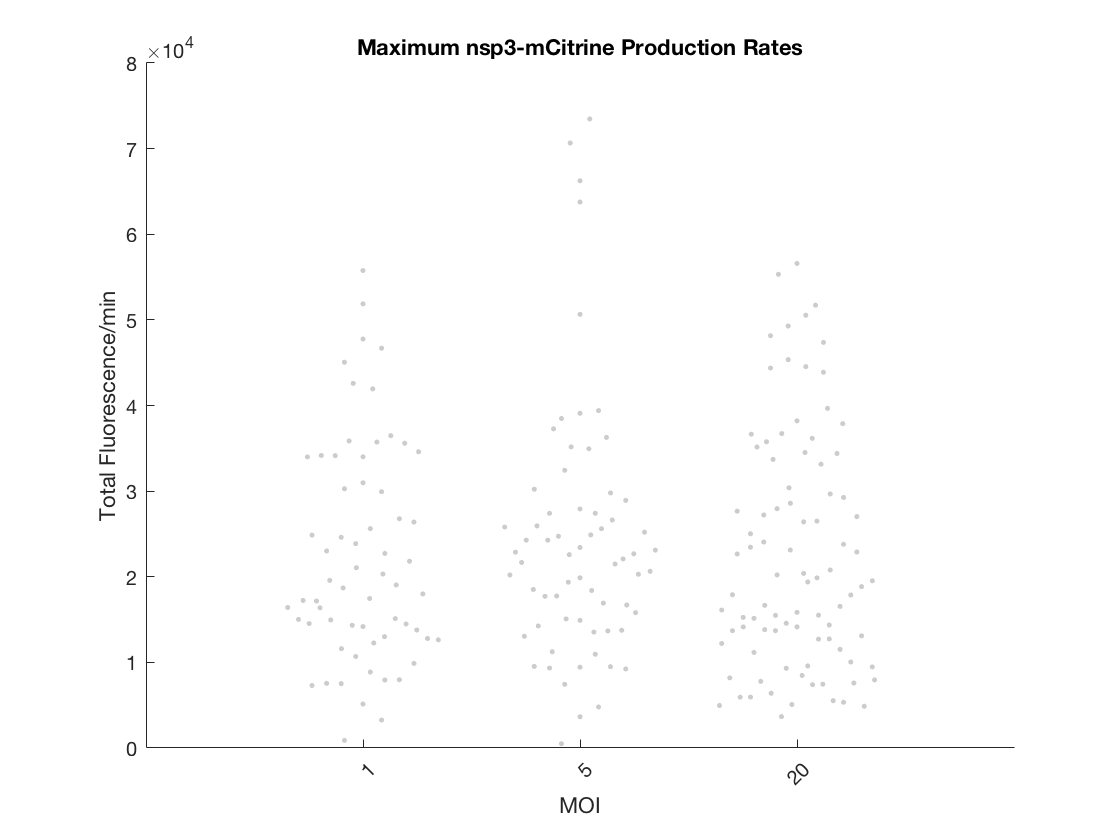

sets={'A3','B1','C1'};
labels={'1','5','20'};

dat=[];
for i=1:length(sets)
    load(fullfile(r_path,'single_virus_traces',[sets{i},'_Tracedata_Cit']));
    dat(i).cit=cell2mat(Tracedata_Cit');
    dat(i).cit=dat(i).cit-repmat(median(dat(i).cit(:,1:4),2),1,size(dat(i).cit,2));
    dat(i).cit=medfilt1(dat(i).cit,5,[],2);
    dat(i).cit=[repmat((dat(i).cit(:,1)),[1 3]), dat(i).cit]; %compensate for first hour un-imaged
    
    dat(i).slope_cit= medfilt1(diff(dat(i).cit,1,2),5,[],2);
    dat(i).slope_cit_max = max(dat(i).slope_cit,[],2);
    dat(i).label=labels(i);
  
    dat(i).Tslopemax=[];
    dat(i).slope_cit_max=[];

    for c=1:size(dat(i).cit,1)
        thisTrace=dat(i).cit(c,:);
        firstDiff=diff(thisTrace,1);
        secondDiff=diff(thisTrace,2);
        
        thisMap=[[1:length(thisTrace)-2]'  firstDiff(1:end-1)' secondDiff'];
        sortedMap=sortrows(thisMap,2,'descend');
        success=0;
        for j=1:3
            if firstDiff(sortedMap(j,1)+1) > 0
                TthisSetslopemax(c)=sortedMap(j,1);
                success=1;
                break;
            end
        end
        if ~success
            dat(i).Tslopemax=[dat(i).Tslopemax NaN];
            dat(i).slope_cit_max=[dat(i).slope_cit_max NaN];
        else
            dat(i).Tslopemax=[dat(i).Tslopemax TthisSetslopemax(c)];
            dat(i).slope_cit_max=[dat(i).slope_cit_max firstDiff(TthisSetslopemax(c))];
        end
    end
end


slopes={};
times={};
times_mean=[];
times_sem=[];
slopes_mean=[];
slopes_sem=[];
for i=1:length(sets)
    slopes{i}=dat(i).slope_cit_max;
    times{i}=dat(i).Tslopemax/3; %converts frames to hours
    good=times{i}<=7;
    times_mean(i)=mean(times{i}(good));
    times_sem(i)=std(times{i}(good));
    slopes_mean(i)=mean(slopes{i}(good));
    slopes_sem(i)=std(slopes{i}(good));
end

figure, plotSpread(slopes,'distributionColor',[.8 .8 .8]), title('Maximum nsp3-mCitrine Production Rates'), xticklabels(labels), xtickangle(45)
xlabel('MOI'),ylabel('Total Fluorescence/min'), hold all; 
ylim([0 8e4])

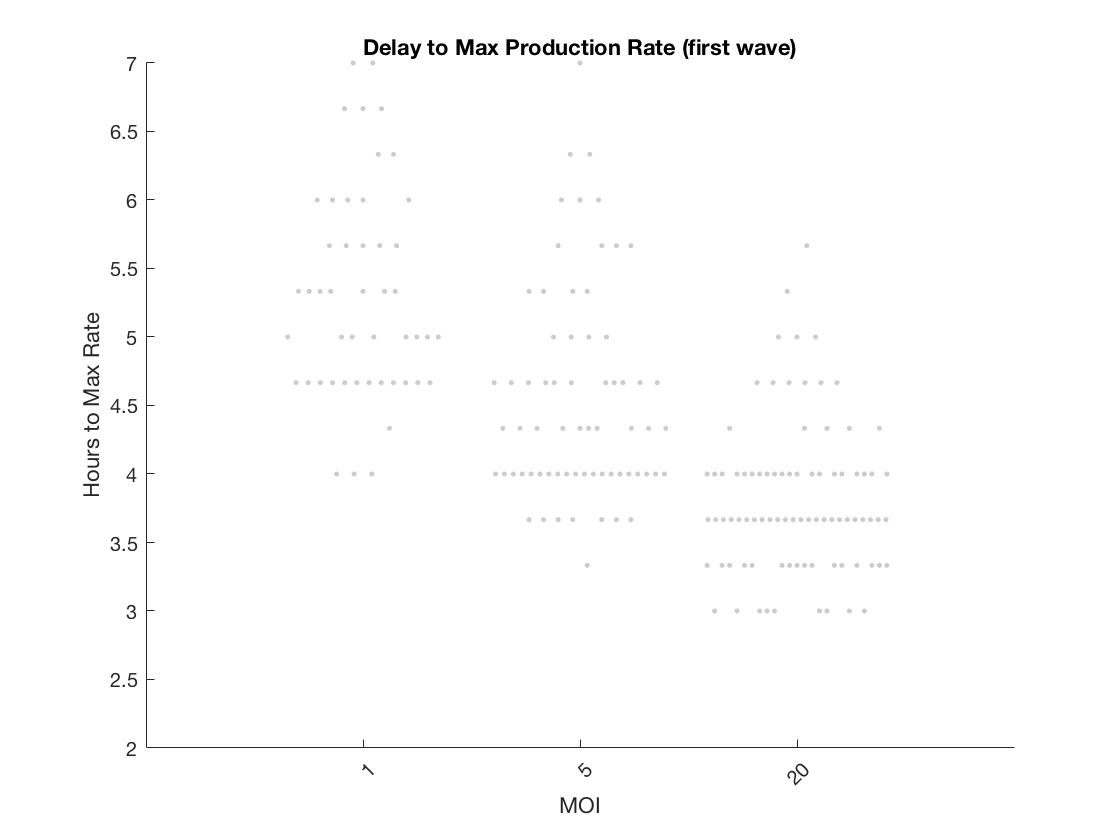

figure, plotSpread(times,'distributionColor',[.8 .8 .8]), title('Delay to Max Production Rate (first wave)'), xticklabels(labels), xtickangle(45), ylabel('Hours to Max Rate')
hold all,xlabel('MOI')
ylim([2 7])


[h,p]=kstest2(dat(1).Tslopemax,dat(2).Tslopemax)

h = logical
   1

p = 3.4281e-07

[h,p]=kstest2(dat(2).Tslopemax,dat(3).Tslopemax)

h = logical
   1

p = 5.5518e-07

[h,p]=kstest2(dat(1).Tslopemax,dat(3).Tslopemax)

h = logical
   1

p = 1.9757e-19


[h,p]=kstest2(dat(1).slope_cit_max,dat(2).slope_cit_max)

h = logical
   0

p = 0.2995

[h,p]=kstest2(dat(2).slope_cit_max,dat(3).slope_cit_max)

h = logical
   0

p = 0.1232

[h,p]=kstest2(dat(1).slope_cit_max,dat(3).slope_cit_max)

h = logical
   0

p = 0.9789

## Superinfection Figures

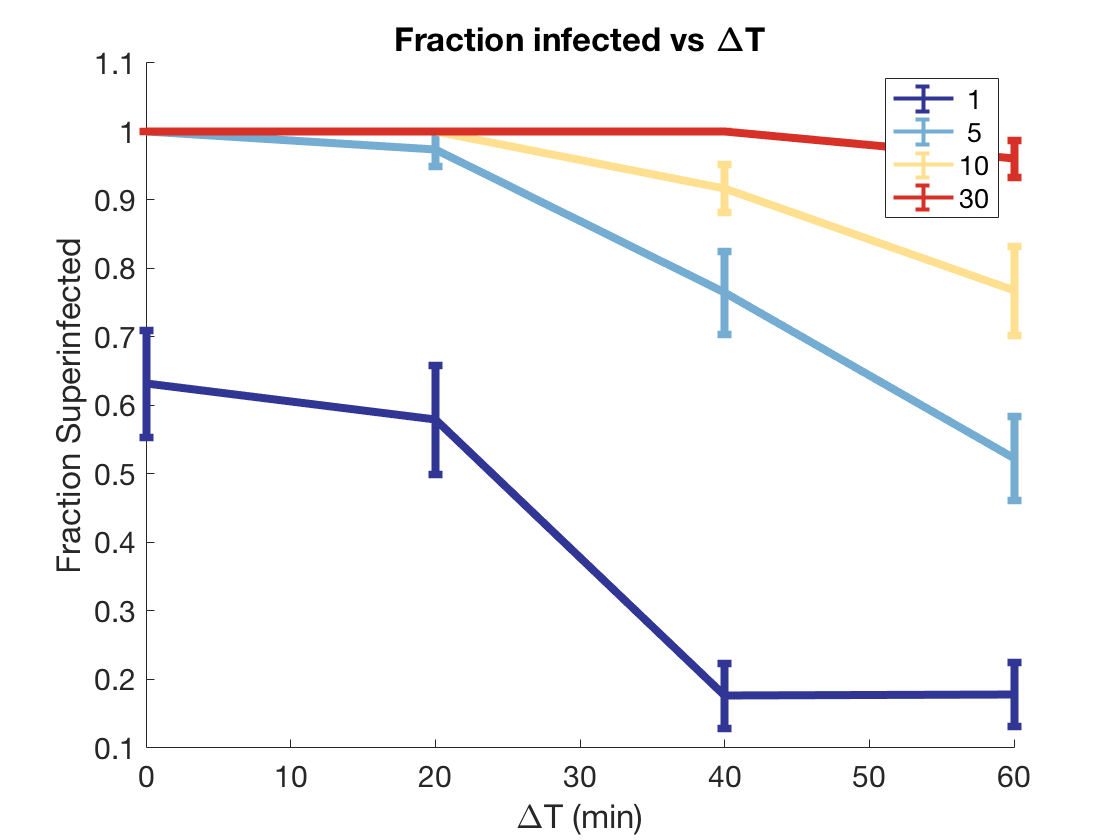

C=[165,0,38;
215,48,39;
254,224,144;
116,173,209;
49,54,149]/255;
C=flip(C,1);


sets = {
    'movie_A2','movie_A3','movie_A4','movie_A5',...
    'movie_B2','movie_B3','movie_B4','movie_B5',...
    'movie_C2','movie_C3','movie_C4','movie_C5',...
    'movie_D2','movie_D3','movie_D4','movie_D5',...
    };

timepoint=48;
load(fullfile(r_path,'se_movie','movie_A6','Tracedata_Cit'));
load(fullfile(r_path,'se_movie','movie_B6','Tracedata_Turq'));
citBG=mean(cell2mat(Tracedata_Cit'),1);
turqBG=mean(cell2mat(Tracedata_Turq'),1);
f=figure; set(gcf,'defaultAxesColorOrder',C)
moi2=[1,5,10,30,1,5,10,30,1,5,10,30,1,5,10,30];
deltaT=[60,60,60,60,40,40,40,40,20,20,20,20,0,0,0,0];
data=struct('MFI',[],'Frac',[]);
onThreshCit=7000; %citrine on treshold > 7000
data={};
for g=1:length(sets)
    load(fullfile(r_path,'se_movie',sets{g},'Tracedata_Cit'));
    Tracedata_Cit=cell2mat(Tracedata_Cit');
    load(fullfile(r_path,'se_movie',sets{g},'Tracedata_Turq'));
    Tracedata_Turq=cell2mat(Tracedata_Turq');
    cit=movmean(Tracedata_Cit-repmat(citBG,size(Tracedata_Cit,1),1),3,2);
    cit=cit-repmat(cit(:,1),1,size(cit,2));
    turq=movmean(Tracedata_Turq-repmat(turqBG,size(Tracedata_Turq,1),1),3,2);
    turq=turq-repmat(turq(:,1),1,size(turq,2));
    
    onCit=cit(:,timepoint)>=onThreshCit;
    
    %resample to compute SE
    trialFrac=[];
    N=length(cit(:,timepoint));
    for r=1:1000
        thisSet=randi(N,1,N);
        theseOnCit=cit(thisSet,timepoint)>=onThreshCit;
        trialFrac(r)=length(find(theseOnCit))/N;
    end
    
    data(g).frac=length(find(onCit))/length(onCit);
    data(g).std_frac=std(trialFrac);
    data(g).mean_cit=mean(cit(onCit,timepoint));
    data(g).se_cit=std(cit(onCit,timepoint))/sqrt(length(onCit));
end

%fix MOI
figure; set(gcf,'defaultAxesColorOrder',C), hold all
toFind=[1,5,10,30];


for i=1:length(toFind)
    f=find(moi2==toFind(i));
    errorbar(deltaT(f),[data(f).frac],[data(f).std_frac],'LineWidth',4)
end
set(gca,'FontSize',15)
xlabel('\DeltaT (min)')
ylabel('Fraction Superinfected')
title('Fraction infected vs \DeltaT')
legend(cellstr(num2str(toFind')))

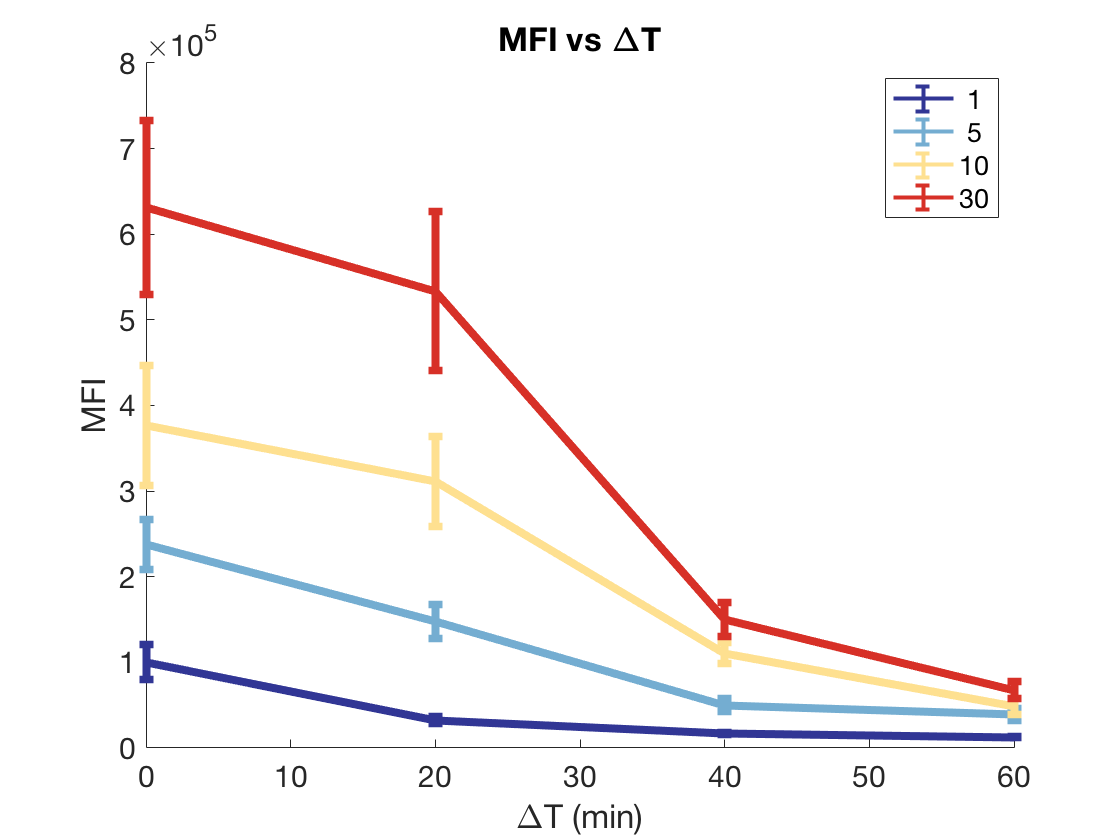


figure; set(gcf,'defaultAxesColorOrder',C); hold all
for i=1:length(toFind)
    f=find(moi2==toFind(i));
    errorbar(deltaT(f),[data(f).mean_cit],[data(f).se_cit],'LineWidth',4)
end
xlabel('\DeltaT (min)')
ylabel('MFI')
title('MFI vs \DeltaT')
legend(cellstr(num2str(toFind')))
set(gca,'FontSize',15)

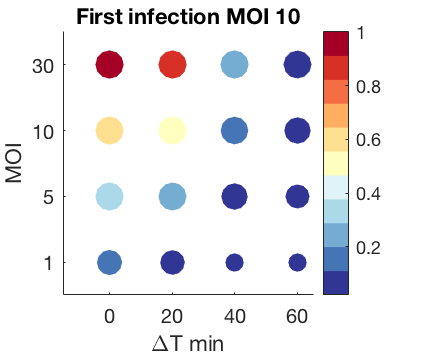




figure
C=[165,0,38;
215,48,39;
244,109,67;
253,174,97;
254,224,144;
255,255,191;
224,243,248;
171,217,233;
116,173,209;
69,117,180;
49,54,149]/255;
C=flip(C,1);

set(gcf,'Position',[1 1 214 178])
colormap(C)
scatter((deltaT),([1,2,3,4,1,2,3,4,1,2,3,4,1,2,3,4]),200*sqrt([data.frac])+eps,[data.mean_cit]/max([data.mean_cit]),'filled')
yticks([1,2,3,4])
xticks([0, 20, 40, 60])
xticklabels({'0','20','40','60'})
yticklabels({1','5','10','30'})
colorbar
xlabel('\DeltaT min')
ylabel('MOI')
ylim([0.5 4.5])
xlim([-15 65])
title('First infection MOI 10')

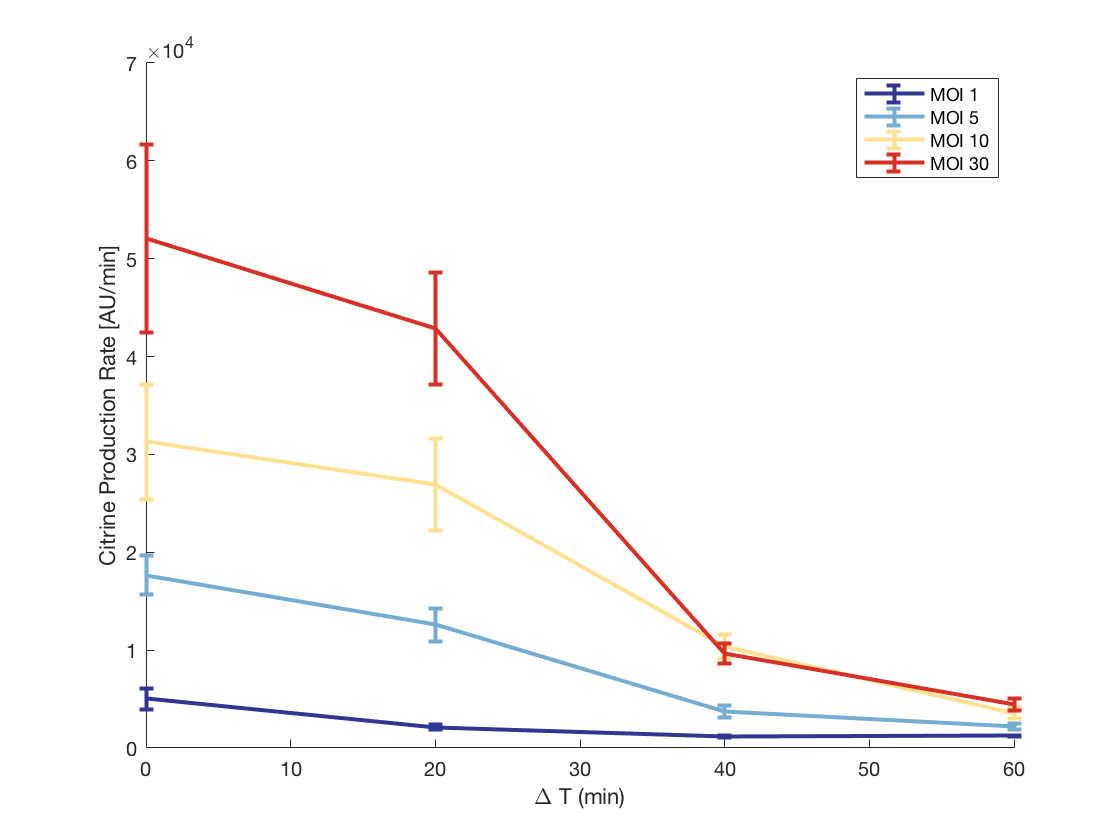


%Fig S3B
sets = {
    {'movie_A2','movie_A3','movie_A4','movie_A5'},...
    {'movie_B2','movie_B3','movie_B4','movie_B5'},...
    {'movie_C2','movie_C3','movie_C4','movie_C5'},...
    {'movie_D2','movie_D3','movie_D4','movie_D5'},...
    };
stats=[];
for r=1:length(sets)
    for c=1:length(sets{r})
        load(fullfile(r_path,'se_movie',sets{r}{c},'Tracedata_Cit'));
        cit=cell2mat(Tracedata_Cit');
        load(fullfile(r_path,'se_movie',sets{r}{c},'Tracedata_Turq'));
        turq=cell2mat(Tracedata_Turq');

        load(fullfile(r_path,'se_movie','movie_A6','Tracedata_Cit'));
        load(fullfile(r_path,'se_movie','movie_B6','Tracedata_Turq'));
        citBG=mean(cell2mat(Tracedata_Cit'),1);
        turqBG=mean(cell2mat(Tracedata_Turq'),1);
        
        cit=movmean(cit-repmat(citBG,size(cit,1),1),3,2);
        cit=cit-repmat(cit(:,1),1,size(cit,2));
        turq=movmean(turq-repmat(turqBG,size(turq,1),1),3,2);
        turq=turq-repmat(turq(:,1),1,size(turq,2));
        
        stats(r,c).cit=medfilt1(cit,5,[],2);
        stats(r,c).turq=medfilt1(turq,5,[],2);
        stats(r,c).slope_cit= diff(cit,1,2);
    end
end

for r=1:size(stats,1)
    for c=1:size(stats,2)
        if ~isempty(stats(r,c).cit)
        stats(r,c).CitSlopeMean=mean(max(stats(r,c).slope_cit(:,1:20),[],2));
        stats(r,c).CitSlopeSD=std(max(stats(r,c).slope_cit(:,1:20),[],2));
        stats(r,c).numCells=size(stats(r,c).cit,1);
        end
    end
end

C=[165,0,38;
215,48,39;
254,224,144;
116,173,209;
49,54,149]/255;
C=flip(C,1);

rVars=[60,40,20,0];
cVars=[0,1,5,10,30];
citSlopesScatter=figure; set(gcf,'defaultAxesColorOrder',C), hold all; 

colors=get(gca,'colororder');
for c=1:4
    figure(citSlopesScatter); 
    hold on
    errorbar(rVars,[stats(1:4,c).CitSlopeMean],[stats(1:4,c).CitSlopeSD]./sqrt([stats(1:4,c).numCells]),'LineWidth',2)
    hold off
end
legend('MOI 1', 'MOI 5','MOI 10','MOI 30'), ylabel('Citrine Production Rate [AU/min]'),xlabel('\Delta T (min)')



%Fig 4H
C=[165,0,38;
215,48,39;
254,224,144;
116,173,209;
49,54,149]/255;
C=flip(C,1);

sets = {
    {'movie_A1','movie_A2','movie_A3','movie_A4','movie_A5'},...
    {'movie_B1','movie_B2','movie_B3','movie_B4','movie_B5'},...
    {'movie_C1','movie_C2','movie_C3','movie_C4','movie_C5'},...
    {'movie_D1','movie_D2','movie_D3','movie_D4','movie_D5'},...
    };

stats=[];
for r=1:length(sets)
    for c=1:length(sets{r})
        load(fullfile(r_path,'se_movie',sets{r}{c},'Tracedata_Cit'));
        cit=cell2mat(Tracedata_Cit');
        load(fullfile(r_path,'se_movie',sets{r}{c},'Tracedata_Turq'));
        turq=cell2mat(Tracedata_Turq');

        load(fullfile(r_path,'se_movie','movie_A6','Tracedata_Cit'));
        load(fullfile(r_path,'se_movie','movie_B6','Tracedata_Turq'));
        citBG=mean(cell2mat(Tracedata_Cit'),1);
        turqBG=mean(cell2mat(Tracedata_Turq'),1);
        
        cit=cit-repmat(citBG,size(cit,1),1);
        cit=cit-repmat(cit(:,1),1,size(cit,2));
        turq=turq-repmat(turqBG,size(turq,1),1);
        turq=turq-repmat(turq(:,1),1,size(turq,2));
        
        stats(r,c).cit=medfilt1(cit,5,[],2);
        stats(r,c).turq=medfilt1(turq,5,[],2);
    end
end

figure; set(gcf,'defaultAxesColorOrder',C); hold all; 
allPointsCit=[];
allPointsCitSEM=[];
allPointsTurq=[];
allPointsTurqSEM=[];
allPointsTime=[];
allPointsGroup=[];
timePoint=48;
for r=1:length(sets)
    thesePoints=[];
    for c=1:length(sets{r})
        thesePoints(c).finalCitMean=mean(stats(r,c).cit(:,timePoint));
        thesePoints(c).finalCitSEM=std(stats(r,c).cit(:,timePoint))/sqrt(size(stats(r,c).cit,1));
        thesePoints(c).finalTurqMean=mean(stats(r,c).turq(:,timePoint));
        thesePoints(c).finalTurqSEM=std(stats(r,c).turq(:,timePoint))/sqrt(size(stats(r,c).turq,1));
        thesePoints(c).numCells=size(stats(r,c).cit,1);
        thesePoints(c).time=c;
        thesePoints(c).group=r;
        allPointsCit=[allPointsCit thesePoints(c).finalCitMean];
        allPointsCitSEM=[allPointsCitSEM thesePoints(c).finalCitSEM];
        allPointsTurq=[allPointsTurq thesePoints(c).finalTurqMean];
        allPointsTurqSEM=[allPointsTurqSEM thesePoints(c).finalTurqSEM];
        allPointsTime=[allPointsTime thesePoints(c).time];
        allPointsGroup=[allPointsGroup thesePoints(c).group];
    end
end
allPtsScatterForLine=scatter(allPointsCit,allPointsTurq); lsline; delete(allPtsScatterForLine);
allPointsCit=[];
allPointsCitSEM=[];
allPointsTurq=[];
allPointsTurqSEM=[];
allPointsTime=[];
allPointsGroup=[];
timePoint=48;
for r=1:length(sets)
    thesePoints=[];
    for c=1:length(sets{r})
        thesePoints(c).finalCitMean=mean(stats(r,c).cit(:,timePoint));
        thesePoints(c).finalCitSEM=std(stats(r,c).cit(:,timePoint))/sqrt(size(stats(r,c).cit,1));
        thesePoints(c).finalTurqMean=mean(stats(r,c).turq(:,timePoint));
        thesePoints(c).finalTurqSEM=std(stats(r,c).turq(:,timePoint))/sqrt(size(stats(r,c).turq,1));
        thesePoints(c).numCells=size(stats(r,c).cit,1);
        thesePoints(c).time=r;
        thesePoints(c).group=c;
        allPointsCit=[allPointsCit thesePoints(c).finalCitMean];
        allPointsCitSEM=[allPointsCitSEM thesePoints(c).finalCitSEM];
        allPointsTurq=[allPointsTurq thesePoints(c).finalTurqMean];
        allPointsTurqSEM=[allPointsTurqSEM thesePoints(c).finalTurqSEM];
        allPointsTime=[allPointsTime thesePoints(c).time];
        allPointsGroup=[allPointsGroup thesePoints(c).group];
        errorbar(thesePoints(c).finalCitMean,thesePoints(c).finalTurqMean,thesePoints(c).finalTurqSEM,thesePoints(c).finalTurqSEM,thesePoints(c).finalCitSEM,thesePoints(c).finalCitSEM,'.','Color',C(c,:));
        scatter(thesePoints(c).finalCitMean,thesePoints(c).finalTurqMean,10*thesePoints(c).time.^2,repmat(C(c,:),length(thesePoints(c)),1),'filled');
        xlim([0 8e5])
        ylim([0 8e6])
    end
end
legend({'\DeltaT=60m','\DeltaT=40m','\DeltaT=20m','\DeltaT=0m'})
set(gca,'FontSize',15)
xlabel('Endpoint Citrine Fluor (AU)')
ylabel('Endpoint Turquoise Fluor (AU)')
corrcoef([thesePoints(:).finalCitMean],[thesePoints(:).finalTurqMean])

ans =     1.0000   -0.9902
   -0.9902    1.0000


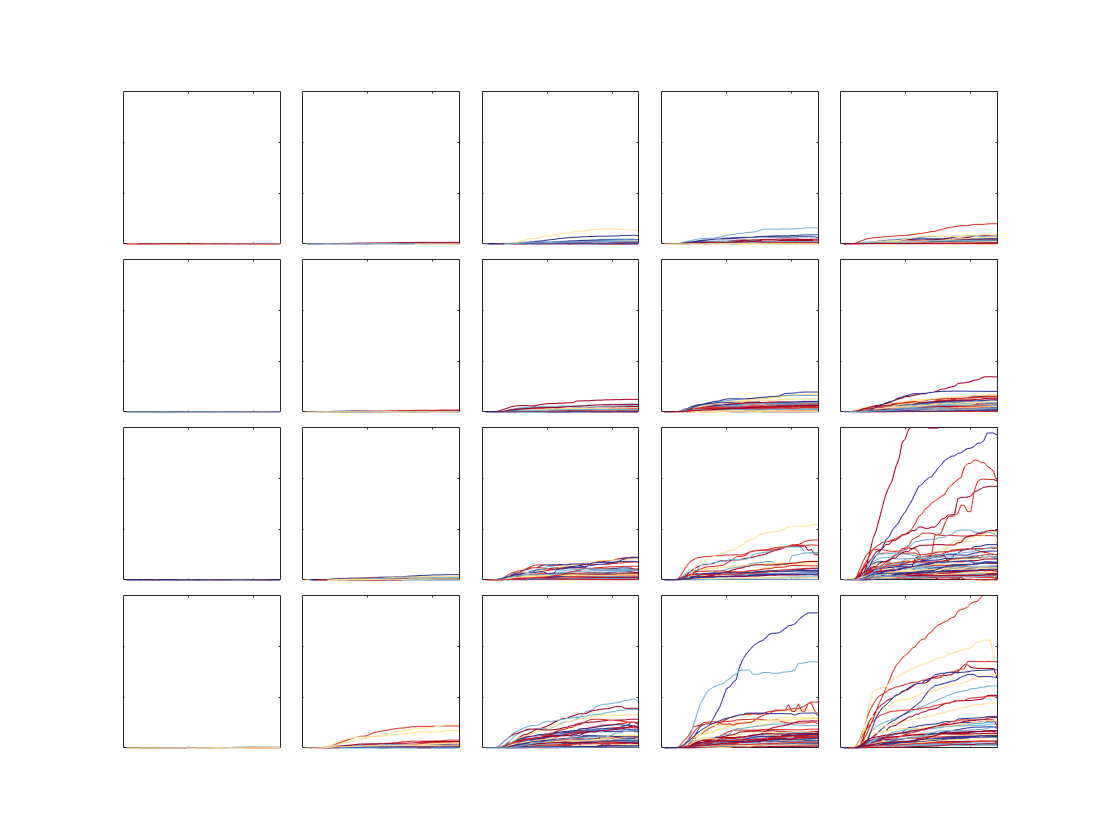

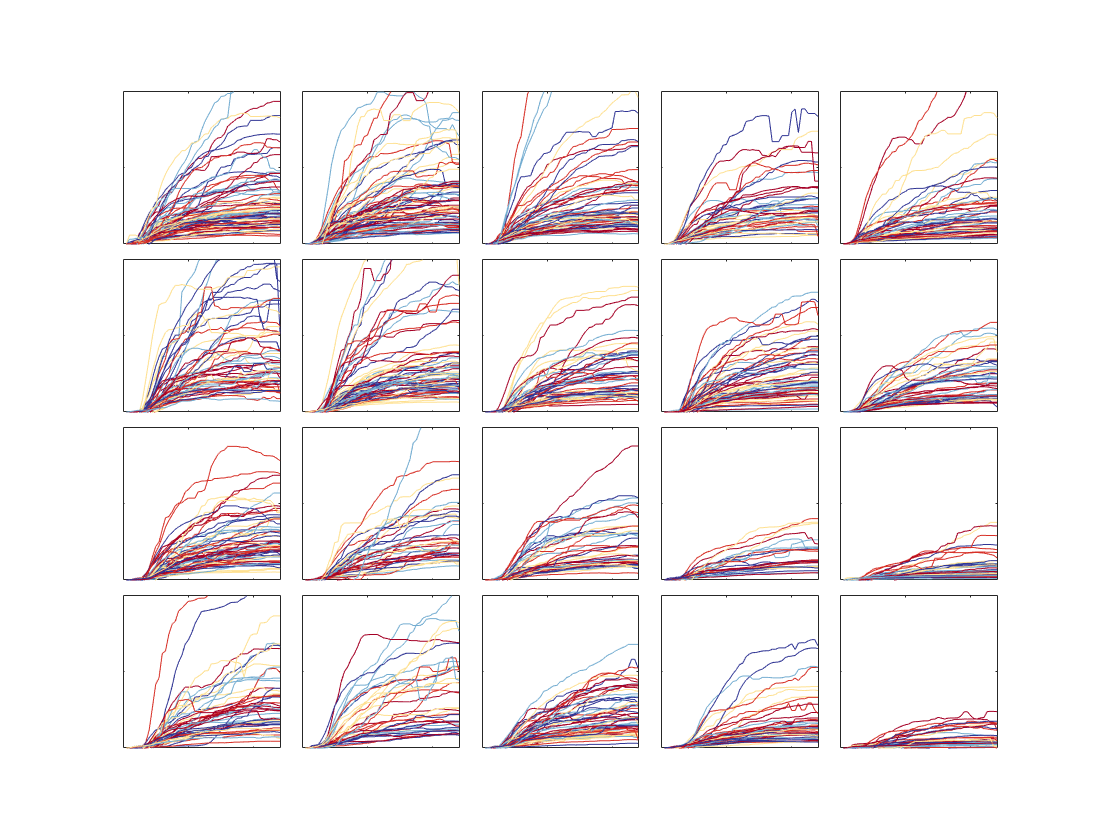



%Figure 4E-F
citFig=figure; subaxis(5,5,1,'Padding',0.01,'Spacing',0), 
turgFig=figure; subaxis(5,5,1,'Padding',0.01,'Spacing',0)
for c=1:5
    for r=1:4
        figure(citFig), set(gcf,'defaultAxesColorOrder',C), subaxis(4,5,sub2ind([5 4],c,r)), plot(stats(r,c).cit'), xlim([0 48]), ylim([0 3e6]),  xticklabels([]), yticklabels([])
        figure(turgFig), set(gcf,'defaultAxesColorOrder',C), subaxis(4,5,sub2ind([5 4],c,r)), plot(stats(r,c).turq'),xlim([0 48]), ylim([0 2e7]),  xticklabels([]), yticklabels([])
    end
end

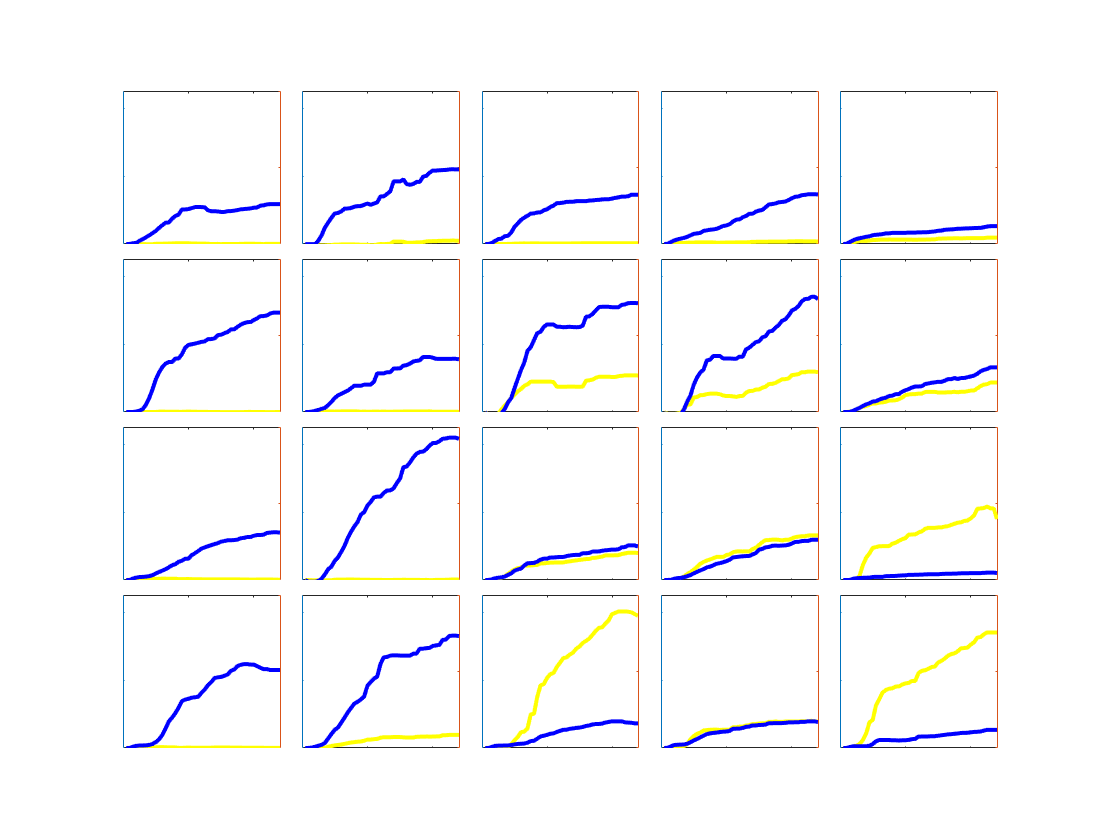


%Figure 4G
twoColorFig=figure; subaxis(5,5,1,'Padding',0.01,'Spacing',0)
for c=1:5
    for r=1:4
        figure(twoColorFig),
        subaxis(4,5,sub2ind([5 4],c,r)), hold all;
        if ~isempty(stats(r,c).cit)
            thisind=5; %this is the index of a particular cell in a given dataset; a combination of cell numbers 3,5,15,8,21, 26 are representative across the different conditions
            yyaxis right, plot(stats(r,c).turq(thisind,:),'b','LineWidth',2),xlim([0 48]),ylim([0 1e7]),xticklabels([]), yticklabels([])
            yyaxis left, plot(stats(r,c).cit(thisind,:),'y','LineWidth',2),xlim([0 48]),ylim([0 4.5e5]),xticklabels([]), yticklabels([])
        end
    end
end



%Figures S3A and S3C
r_path='./'

r_path = './'

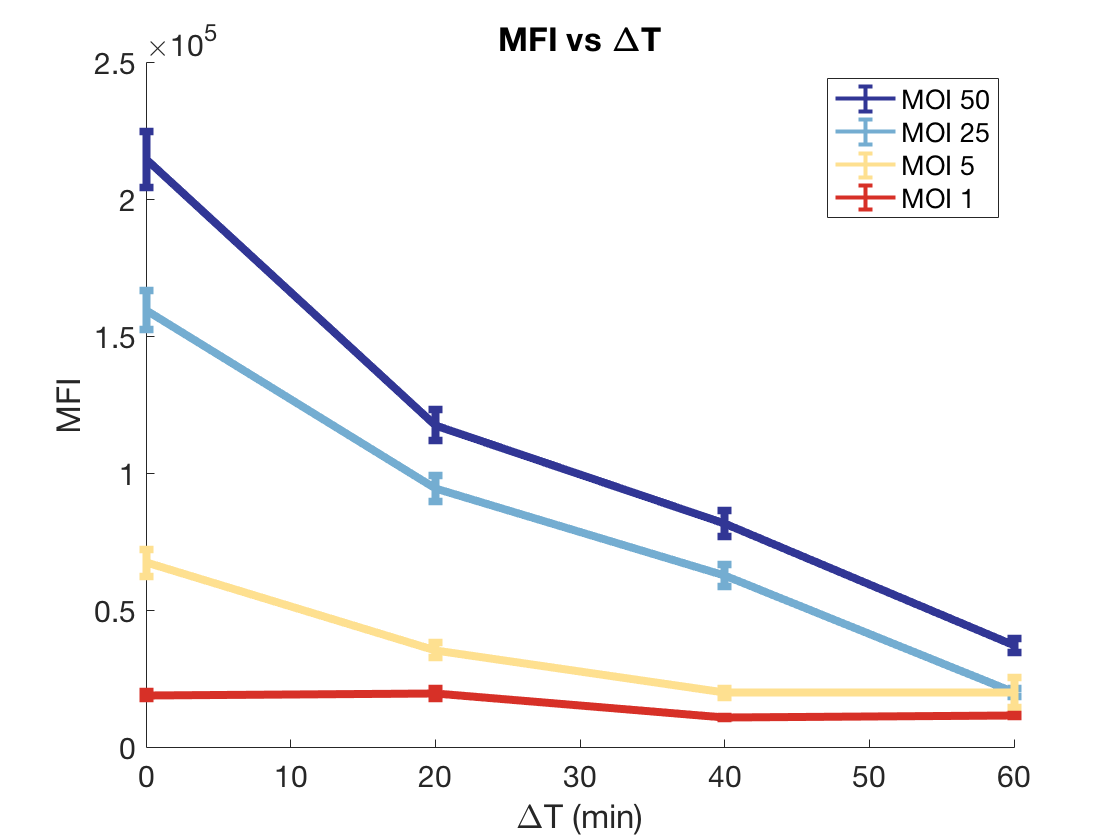


C=[    165,0,38;
215,48,39;
254,224,144;
116,173,209;
49,54,149]/255;
C=flip(C,1);

groups = {
    {'movie_A1','movie_A2','movie_A3','movie_A4','movie_A5','movie_A6'}... %-60m
    {'movie_B1','movie_B2','movie_B3','movie_B4','movie_B5','movie_B6'}... %-40m
    {'movie_C1','movie_C2','movie_C3','movie_C4','movie_C5','movie_C6'}... %-20m
    {'movie_D1','movie_D2','movie_D3','movie_D4','movie_D5'}... %0m
    };
timePoint=36; %12hpi
h2=figure;set(gcf,'defaultAxesColorOrder',C); hold all

M=[];
for c=5:-1:2
    m1=[];
    se1=[];
    m2=[];
    se2=[];
    for r=1:4
        d=dir(fullfile(r_path,'se_movie_gfp_mch',[groups{r}{c},'*stats.mat']));
        x=load(fullfile(r_path,'se_movie_gfp_mch',d(1).name),'rt');
        lastTimePoint=length(x.rt);
        
        m2(r)=mean(x.rt{timePoint}.totalF2);
        se2(r)=std(x.rt{timePoint}.totalF2)/sqrt(length(x.rt{timePoint}.totalF2));
        
        M(r,c-1).scar=x.rt{timePoint}.totalF;
        M(r,c-1).gfp=x.rt{timePoint}.totalF2;        
    end        
        figure(h2)
        errorbar([60,40,20,0],m2,se2,'LineWidth',4)
end

xlabel('\DeltaT (min)')
ylabel('MFI')
title('MFI vs \DeltaT')
legend('MOI 50','MOI 25','MOI 5','MOI 1')
set(gca,'FontSize',15)


figure; hold all;
allPointsgfp=[];
allPointsgfpSEM=[];
allPointsscar=[];
allPointsscarSEM=[];
allPointsTime=[];
allPointsGroup=[];
timePoint=1;

for r=1:4
    thesePoints=[];
    for c=1:size(M,2)
        thesePoints(c).finalgfpMean=mean(M(r,c).gfp(:,timePoint));
        thesePoints(c).finalgfpSEM=std(M(r,c).gfp(:,timePoint))/sqrt(size(M(r,c).gfp,1));
        thesePoints(c).finalscarMean=mean(M(r,c).scar(:,timePoint));
        thesePoints(c).finalscarSEM=std(M(r,c).scar(:,timePoint))/sqrt(size(M(r,c).scar,1));
        thesePoints(c).numCells=size(M(r,c).gfp,1);
        thesePoints(c).time=r;
        thesePoints(c).group=c;
        allPointsgfp=[allPointsgfp thesePoints(c).finalgfpMean];
        allPointsgfpSEM=[allPointsgfpSEM thesePoints(c).finalgfpSEM];
        allPointsscar=[allPointsscar thesePoints(c).finalscarMean];
        allPointsscarSEM=[allPointsscarSEM thesePoints(c).finalscarSEM];
        allPointsTime=[allPointsTime thesePoints(c).time];
        allPointsGroup=[allPointsGroup thesePoints(c).group];
    end
end
allPtsScatterForLine=scatter(allPointsgfp,allPointsscar); lsline; delete(allPtsScatterForLine);
corrcoef([thesePoints(:).finalgfpMean],[thesePoints(:).finalscarMean])

ans =     1.0000   -0.9859
   -0.9859    1.0000


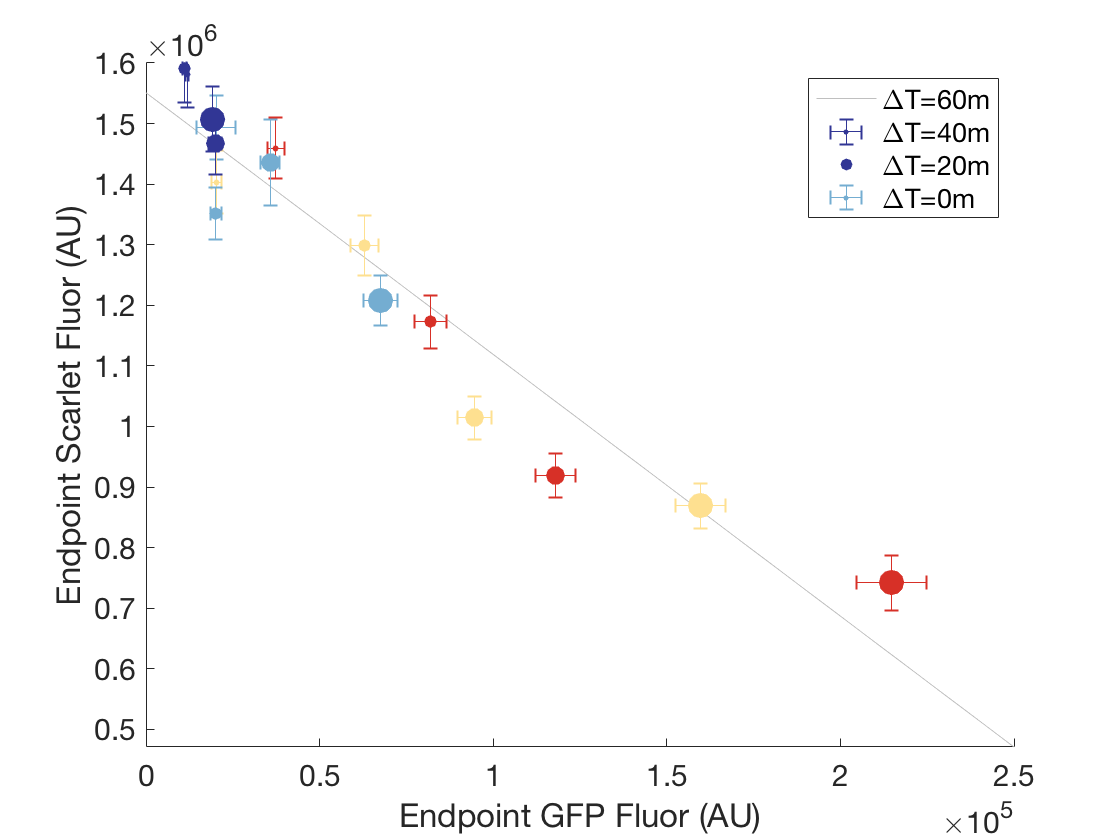


allPointsgfp=[];
allPointsgfpSEM=[];
allPointsscar=[];
allPointsscarSEM=[];
allPointsTime=[];
allPointsGroup=[];
timePoint=1;

for r=1:4
    thesePoints=[];
    for c=1:size(M,2)
        thesePoints(c).finalgfpMean=mean(M(r,c).gfp(:,timePoint));
        thesePoints(c).finalgfpSEM=std(M(r,c).gfp(:,timePoint))/sqrt(size(M(r,c).gfp,1));
        thesePoints(c).finalscarMean=mean(M(r,c).scar(:,timePoint));
        thesePoints(c).finalscarSEM=std(M(r,c).scar(:,timePoint))/sqrt(size(M(r,c).scar,1));
        thesePoints(c).numCells=size(M(r,c).gfp,1);
        thesePoints(c).time=r;
        thesePoints(c).group=c;
        allPointsgfp=[allPointsgfp thesePoints(c).finalgfpMean];
        allPointsgfpSEM=[allPointsgfpSEM thesePoints(c).finalgfpSEM];
        allPointsscar=[allPointsscar thesePoints(c).finalscarMean];
        allPointsscarSEM=[allPointsscarSEM thesePoints(c).finalscarSEM];
        allPointsTime=[allPointsTime thesePoints(c).time];
        allPointsGroup=[allPointsGroup thesePoints(c).group];
        errorbar(thesePoints(c).finalgfpMean,thesePoints(c).finalscarMean,thesePoints(c).finalscarSEM,thesePoints(c).finalscarSEM,thesePoints(c).finalgfpSEM,thesePoints(c).finalgfpSEM,'.','Color',C(c,:));
        scatter(thesePoints(c).finalgfpMean,thesePoints(c).finalscarMean,10*thesePoints(c).time.^2,repmat(C(c,:),length(thesePoints(c)),1),'filled');
    end
end


legend({'\DeltaT=60m','\DeltaT=40m','\DeltaT=20m','\DeltaT=0m'})
set(gca,'FontSize',15)
xlabel('Endpoint GFP Fluor (AU)')
ylabel('Endpoint Scarlet Fluor (AU)')



corrcoef([thesePoints(:).finalgfpMean],[thesePoints(:).finalscarMean])

ans =     1.0000   -0.9859
   -0.9859    1.0000


## Simulations

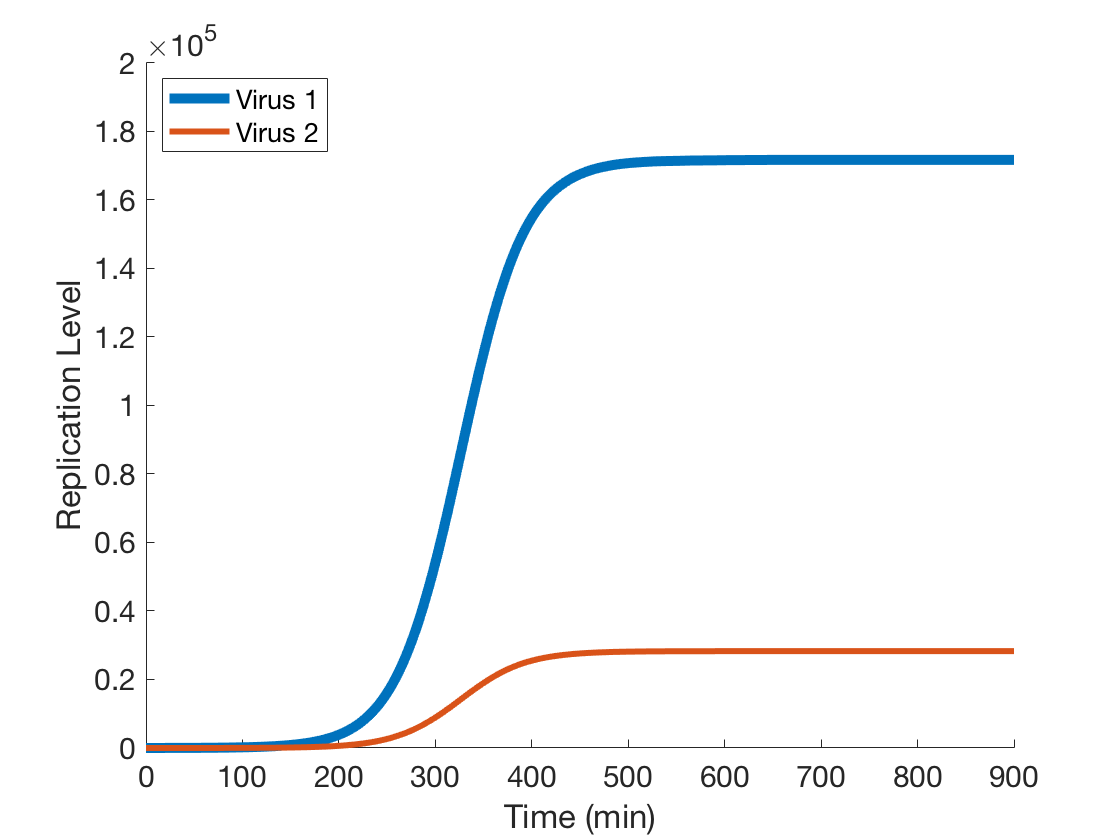


C=[165,0,38;
215,48,39;
254,224,144;
116,173,209;
49,54,149]/255;
C=flip(C,1);
[t,v1,v2]=simVir(10,10,60,15*60);
figure, hold all;
plot(t,v1,'LineWidth',5);
plot(t,v2,'LineWidth',3);
legend('Virus 1', 'Virus 2','Location','NW')
set(gca,'FontSize',15)
xlim([0 15*60]), ylim([0 2e5])
xlabel('Time (min)')
ylabel('Replication Level')

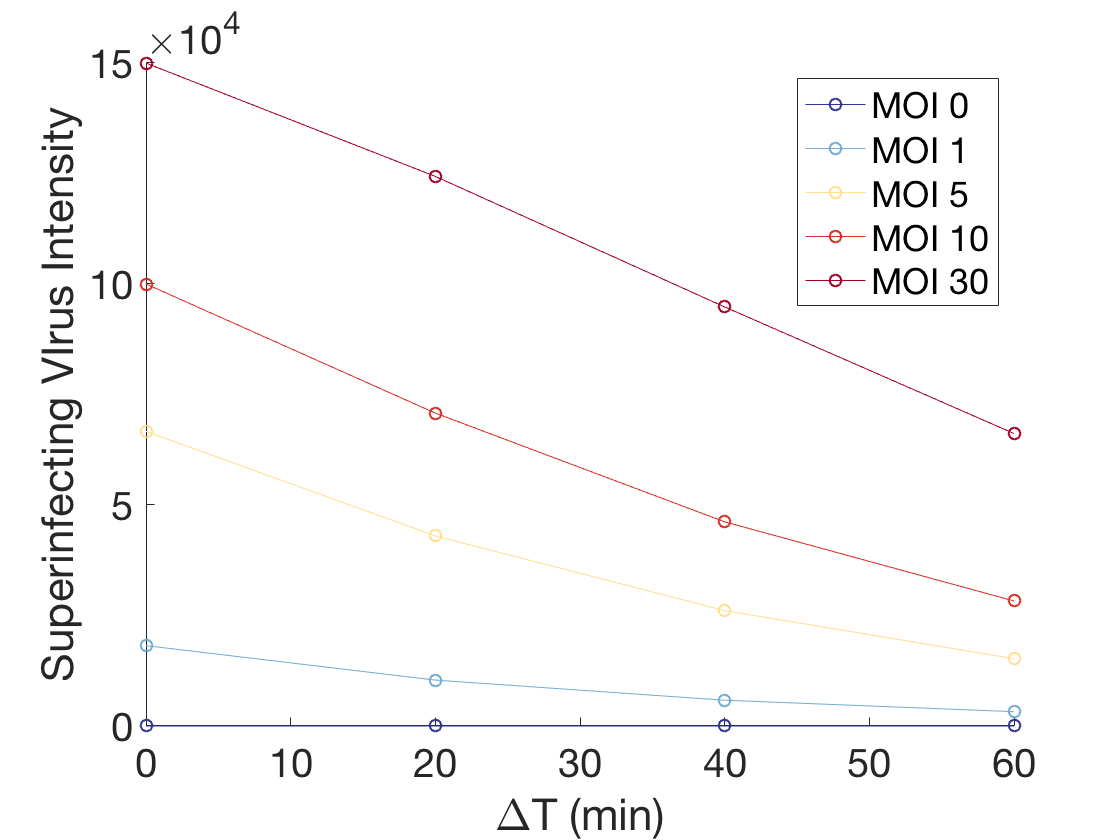


times=[60,40,20,0];
v2mois=[0,1,5,10,30];
Mend=[];
for thisT=1:length(times)
    for m=1:length(v2mois)
            [t,v1,v2]=simVir(10,v2mois(m),times(thisT),720);
            Mend(thisT,m).v1end=v1(end);
            Mend(thisT,m).v2end=v2(end);
            Mend(thisT,m).v1maxSlope=max(diff(v1));
            Mend(thisT,m).v2maxSlope=max(diff(v2));
    end
end

rVars=[60,40,20,0];
cVars=[0,1,5,10,30];
figure; set(gcf,'defaultAxesColorOrder',C); hold all;  
for c=1:5
    plot(rVars,[Mend(1:4,c).v2end],'-o')
end
xlabel('\DeltaT (min)'); ylabel('Superinfecting VIrus Intensity')
legend('MOI 0', 'MOI 1','MOI 5','MOI 10','MOI 30')
set(gca,'FontSize',20)

function [t,v1,v2]=simVir(v1_t0,v2_tTau,tau,tEnd)

K=2e5;
a1=.03;

%%%%%%
p(1)=K;
p(2)=a1;
if tau>0
    y0=[v1_t0,0];
    tspan1=[0 tau];
    
    d1 = ode15s(@(t,y) ode_sindbis_comp(t,y,p), tspan1, y0);
    t_tspan1=0:tau;
    y_tspan1=deval(d1,t_tspan1)';
    y_tspan1(end,2)=v2_tTau;
    
    t_tspan2=[0 tEnd-tau];
    d2 = ode15s(@(t,y) ode_sindbis_comp(t,y,p), t_tspan2, y_tspan1(end,:));
    y_tspan2=deval(d2,0:(tEnd-tau-1))';
    
    merge_t=0:tEnd;
    merge_y=[y_tspan1; y_tspan2];
else
    y0=[v1_t0,v2_tTau];
    tspan=[0 tEnd];
    d1 = ode15s(@(t,y) ode_sindbis_comp(t,y,p), tspan, y0);
    yspan=deval(d1,0:tEnd);
    merge_t=0:tEnd;
    merge_y=yspan';
end
t=merge_t;
v1=merge_y(:,1);
v2=merge_y(:,2);
end


function dydt=ode_sindbis_comp(t,y,p)
V1=y(1);
V2=y(2);

K=p(1);
a=p(2);


dydt(1)=a*V1*(1-(V1+V2)/K);
dydt(2)=a*V2*(1-(V1+V2)/K);

dydt=reshape(dydt,[],1);
end

function [t,v1,v2]=simVirPassingParams(a1,K,v1_t0,v2_tTau,tau,tEnd)

p(1)=K;
p(2)=a1;
if tau>0
    y0=[v1_t0,0];
    tspan1=[0 tau];
    tspan2=[tau tEnd];
    [t_tspan1,y_tspan1] = ode15s(@(t,y) ode_sindbis_comp(t,y,p), tspan1, y0);
    y_tspan1(end,2)=v2_tTau;
    [t_tspan2,y_tspan2] = ode15s(@(t,y) ode_sindbis_comp(t,y,p), tspan2, y_tspan1(end,:));
    
    merge_t=[t_tspan1; t_tspan2];
    merge_y=[y_tspan1; y_tspan2];
else
    y0=[v1_t0,v2_tTau];
    tspan1=[0 tEnd];
    [t_tspan1,y_tspan1] = ode15s(@(t,y) ode_sindbis_comp(t,y,p), tspan1, y0);
    merge_t=[t_tspan1];
    merge_y=[y_tspan1];
end
t=merge_t;
v1=merge_y(:,1);
v2=merge_y(:,2);
end